# **Multimeridian MB Mode Acquisition Simulation - Version 4.0 - Ideal (No Saccades) - Cylindrical Waveprop (Homogeneous, No Inclusion) - Quasi-Harmonic Temporal Profile**

**Author: Estéfano Machado Ferrer**

**For comparison with the newly proposed SBM Protocol and general assessment and testing with the MB Mode Protocol**

**Creation Date of Version 4.0 (DD/MM/YY): 18-05-2026**

**Last Modified Date (DD/MM/YY): 08-06-2026**

clc; clear; close all

Start timer:

tic

add codes path:

codes_path = fullfile(pwd, "Codes");   % open MATLAB in the repository root
addpath(genpath(codes_path));          % also adds Codes/k-Wave

## Experiment and file parameters for analysis and storage

Number of Meridians and spatial samples per meridian for Multimeridian MB Mode Sampling Simulation:

Number_Meridians = 8;
nAscans_per_meridian = 100; % A-lines per meridian

Base path for results:

base_path = fullfile(fileparts(codes_path), "Results");
protocol_type = "Multimeridian_MB";
protocol_path = strcat(base_path,"/",protocol_type);

try
    cd(protocol_path);
catch
    mkdir(protocol_path);
    cd(protocol_path);
end

Build/load path for specific number of meridians:

num_mer_path = sprintf("%d Meridians",Number_Meridians);
try
    cd(num_mer_path);
catch
    mkdir(num_mer_path);
end
run_path = pwd;

## Wave Propagation Simulation - Physical Phenomena

Recall that the Spherical Wave Equation, i.e. a restricted solution to the Helmholtz Equation is:

### 
$$\left( \mathbf{\nabla} ^2 - \frac{1}{c^2} \frac{\partial^2}{\partial t^2} \right) u(r,t) = 0$$


Then the *monochromatic* (harmonic, one frequency) solution to the wave equation is:

### 
$$u(r,t) = \frac{A}{r} \Re\{ e^{i\left( \omega t \pm \textbf{k} r\right)}\}$$


We'll implement this in a medium that has uniform background sound speed $c$, and we'll choose that value to be $c = 10$ m/s (observed average lamb wave phase speed in healthy human corneas), this corresponds to the perfectly cylindrical case.

Also in order to include the attenuation term, we make the wavenumber complex in the following fashion:

### 
$$\textbf{k} =  \frac{\omega_{\text{excitation}}}{c} + i \cdot \alpha$$


By defining $c$ as a matrix with different values we can simulate the wave propagation behavior of a heterogeneous medium, such as biological tissues like the Cornea.

In practice a lot more parameters must be defined for a succesful simulation scheme, hence why we'll use a more sophisticated toolbox such as the k-Wave toolbox [1], based on the k-Space Pseudospectral Method to simulate our wave propagation in both healthy and "keratoconic" or ectatic corneas.

About attenuation in the k-Wave toolbox [1]:

k-Wave models acoustic absorption using a frequency power law of the form $\alpha = \alpha_0 \omega^y$, where $\alpha_0$ is the absorption prefactor and $y$ is the power law exponent. In the full model, absorption is physically coupled with dispersion, meaning the phase velocity can become frequency-dependent.

For this simulation, attenuation is only used as an amplitude-decay mechanism. Therefore, dispersion is disabled with `medium.alpha_mode = 'no_dispersion'`, and attenuation can be set to zero with `alpha = 0` when the goal is to preserve the wavelength and isolate speed-estimation errors caused by the acquisition protocol and medium geometry.

[1] Treeby, B. E., & Cox, B. T. (2010). k-Wave: MATLAB toolbox for the simulation and reconstruction of photoacoustic wave fields. *Journal of Biomedical Optics*, *15*(2), 021314. https://doi.org/10.1117/1.3360308

### Define Simulation Parameters

%Define the medium's "background" sound speed
c_medium = 10; % [m/s]
% Define sampling period of the OCT system:
Ts_OCT = 5e-6; % [s]
% Define the excitation's period:
T_excitation = 285e-6; % Excitation period (must be a multiple of Ts_OCT)
% Attenuation coefficient:
attenuation = 0; % [Np/m]
alpha = attenuation*(20/log(10)); % [dB/m] 
% Number of periods of the excitation waveform we want to simulate
N_pulses = 3;
% Number of excitation ensembles we want to simulate:
N_excitations = 2;
% Peak amplitude of the Oscillations:
A_Peak = 1;

And for the quasi harmonic modulation period, the quasi-harmonic parameters: M-repetitions (temporal samples per spatial position) and sync samples

M_repetitions = 200; % temporal samples per spatial position
nSyncSamples = 50;   % number of samples to discretize each transition turn

#### Define Computational Grid

% Dimensions of the Computational Grid in mm:
horizontalMin = -6; horizontalMax = 6; % x axis: 12 mm -> from -6 to 6 mm
verticalMin = -6; verticalMax = 6; % y axis: 12 mm -> from -6 to 6 mm
% Number of spatial points:
nPoints = 500; % Number of points on each dimension

### Simulation using k-Wave

#### Define propagation type

prop_type = 'K_Wave_Harmonic_CustomMedium'; % Options: 'Wave_Eq_Harmonic_Cylindrical','K_Wave_Quasi_Harmonic_CustomMedium','K_Wave_Harmonic_CustomMedium'

#### Use GUI for Medium Definition

Run only first when defining medium

% sim_opts = struct();
% sim_opts.useGUI = true;
% sim_opts.saveConfig = true;
% sim_opts.M_repetitions = M_repetitions;
% sim_opts.nSyncSamples = nSyncSamples;
% sim_opts.showSourceDiagnostics = false;

#### Headless Medium Definition

Run for batch simulations (GUI had to be run at least once)

sim_opts = struct();
sim_opts.useGUI = false;
sim_opts.saveConfig = false;
sim_opts.M_repetitions = M_repetitions;
sim_opts.nSyncSamples = nSyncSamples;
sim_opts.showSourceDiagnostics = false;

#### Compute Simulation

k-Wave attenuation disabled: alpha = 0 dB/m
Filtering input signal...
  maximum frequency supported by kgrid: 125kHz (2 PPW)
  filter cutoff frequency: 83.3333kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 17-Jun-2026 13:39:26
  reference sound speed: 10m/s
  dt: 5us, t_end: 2.68ms, time steps: 537
  input grid size: 500 by 500 grid points (12 by 12mm)
  maximum supported frequency: 125kHz
  casting variables to single type...


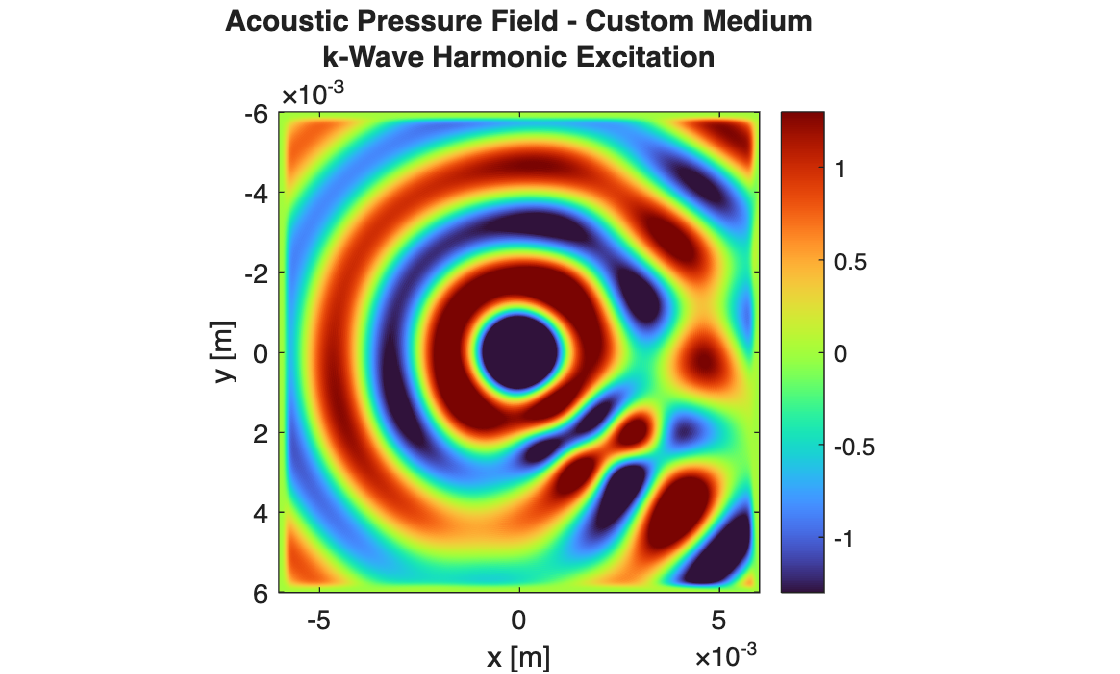

[WaveProp_Vid, x_grid, y_grid, t_grid, GT_SpeedMap] = Wave_Prop_Simulation_v3( ...
    c_medium, Ts_OCT, T_excitation, alpha, N_pulses, A_Peak, ...
    horizontalMin, horizontalMax, verticalMin, verticalMax, ...
    nPoints, N_excitations, prop_type, sim_opts);

#### Ground Truth Phase Speed Values used for Simulation

Display ground truth speed map (cropped):

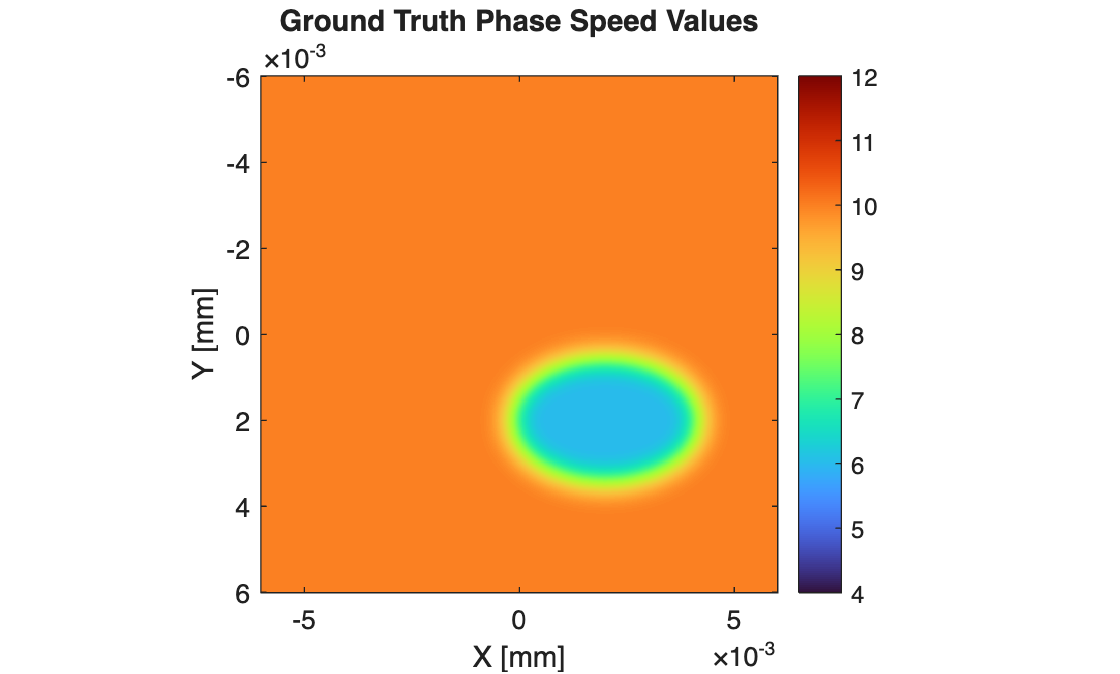

figure, colormap("turbo")
imagesc(x_grid, y_grid,GT_SpeedMap), colorbar, clim([4 12])
axis image;
xlabel('X [mm]'); ylabel('Y [mm]');
title({"Ground Truth Phase Speed Values",""})

#### Space-Time Map of Simulation

And finally, we compute the space-time map for analysis:

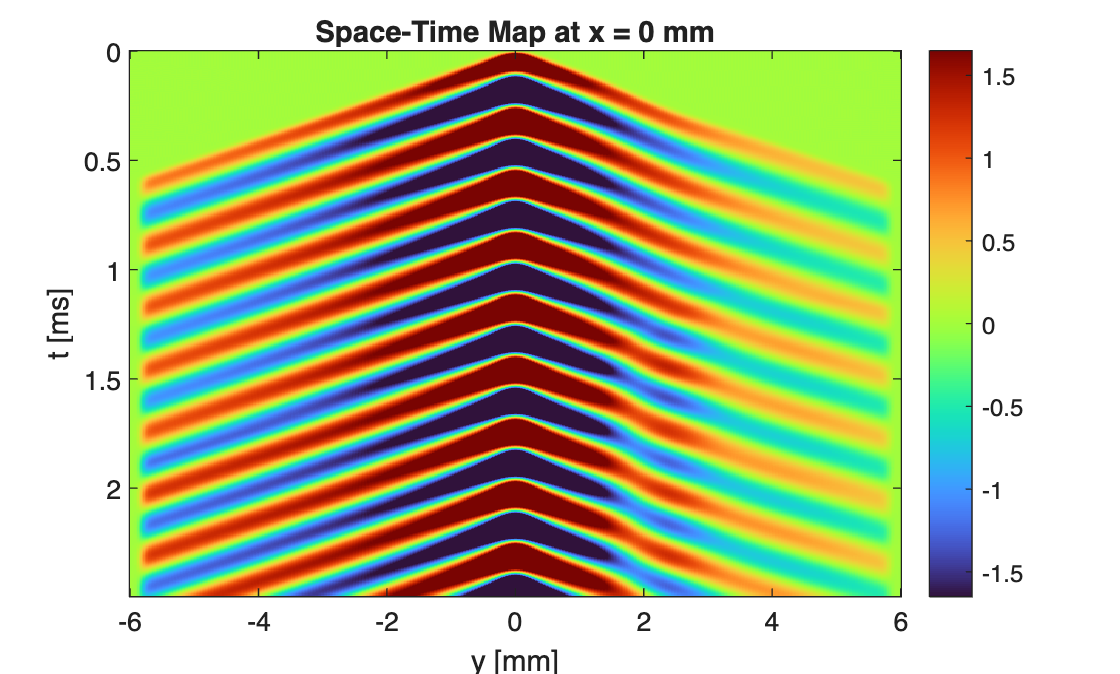

% Set up robust colormap: mean ± 1 sd:
mean_Im_Uz = mean(reshape(WaveProp_Vid,1,[]));
std_Im_Uz = std(reshape(WaveProp_Vid,1,[]));
clim_low = mean_Im_Uz - 2*std_Im_Uz;
clim_high = mean_Im_Uz + 2*std_Im_Uz;
clim_robust = min(abs(clim_low),abs(clim_high));

% Plot Figure:
f_ST = figure(2);
imagesc(x_grid*1e3,t_grid*1e3,squeeze(WaveProp_Vid(:,round(length(y_grid)/2),:)).');
title("Space-Time Map at x = 0 mm")
xlabel("y [mm]")
ylabel("t [ms]")
set(gca,'YDir','reverse'); axis tight;
colormap("turbo"); 
colorbar;
clim([-clim_robust clim_robust])

% ylim([0 2])

## Segmentation Masks: Background and Inclusions

[Bkg_Mask, Inc_Mask] = Get_Bkg_ROI_Masks( ...
    GT_SpeedMap, 'BgTolFrac', 0.04, 'IncTolFrac', 0.20, 'MarginPx', 10);

Visualize masks:

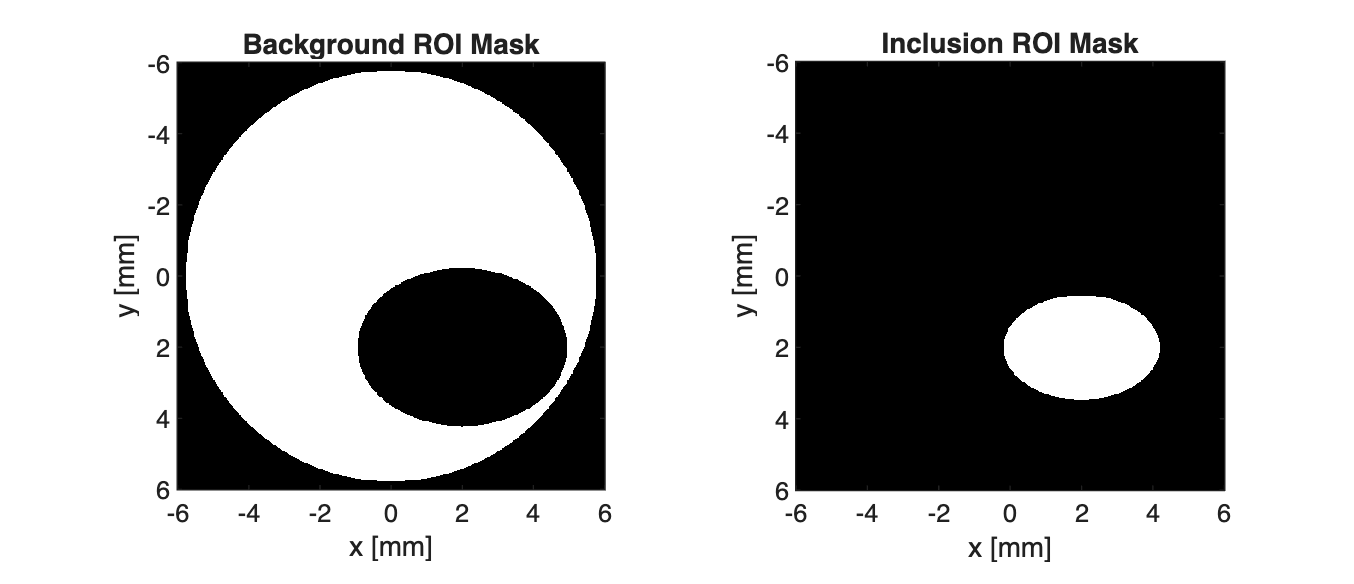

% Background (Bkg) Mask:
figure,
tiledlayout(1,2)
nexttile
imagesc(x_grid*1e3, y_grid*1e3, Bkg_Mask)
set(gca, 'YDir', 'reverse')
axis image
colormap(gca, gray)
title('Background ROI Mask')
xlabel('x [mm]')
ylabel('y [mm]')
xticks(-6:2:6);
% Inclusion Mask:
nexttile
imagesc(x_grid*1e3, y_grid*1e3, Inc_Mask)
set(gca, 'YDir', 'reverse')
axis image
colormap(gca, gray)
title('Inclusion ROI Mask')
xlabel('x [mm]')
ylabel('y [mm]')
xticks(-6:2:6);
set(gcf,"Position",0.6.*[1,1,1128,450]);

Visualize how the masking effect in the Ground Truth speed map:

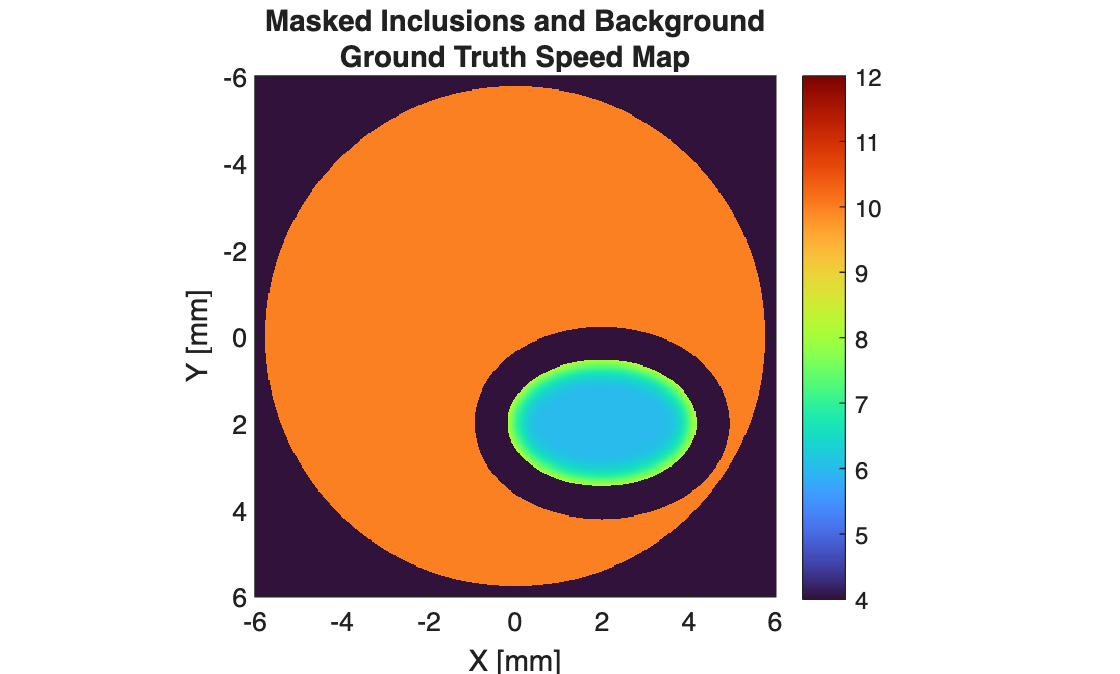

figure,
imagesc(x_grid*1e3, y_grid*1e3,GT_SpeedMap.*Bkg_Mask + GT_SpeedMap.*Inc_Mask);
clim([4 12]);
colormap("turbo"); colorbar;
title({"Masked Inclusions and Background"...
      ,"Ground Truth Speed Map"});
axis image;
xlabel('X [mm]'); ylabel('Y [mm]'); xticks(-6:2:6);

## 2D Phase Gradient Speed Estimation in OG Wave Prop

PhaseGradient2D_FromSims_v3()
Phase-gradient estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=5e-06 s (fs=200000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=19 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)


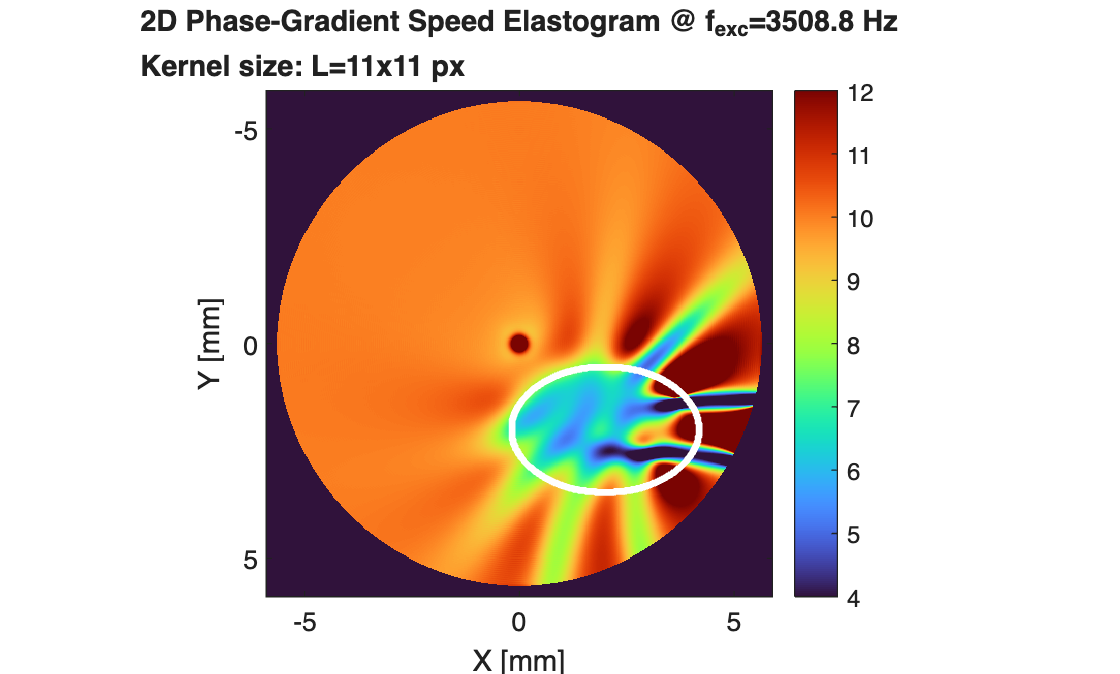

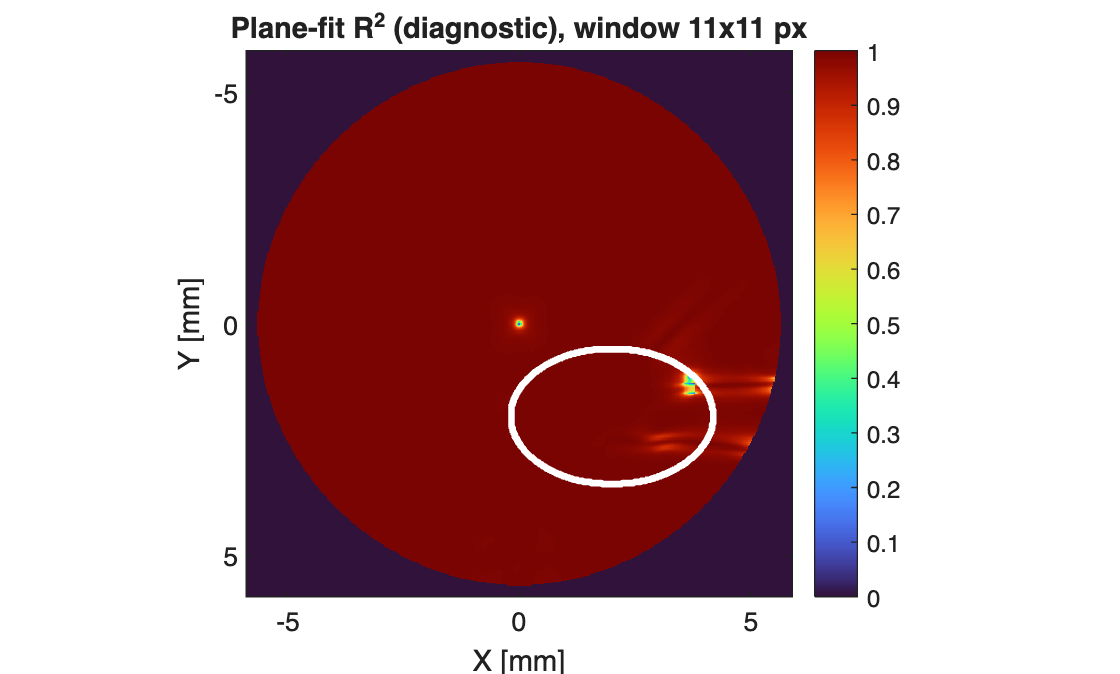

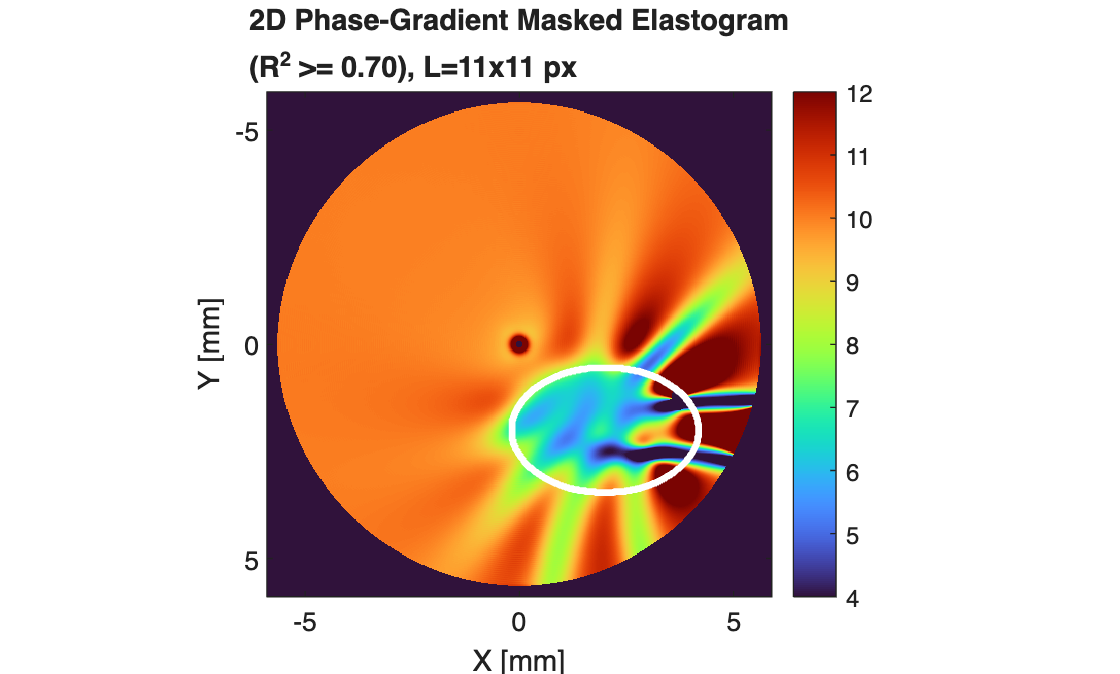

kernel_size = 11; % L x L window for estimation
applyTemporalWindow = true;
% Color limits for 2D PG estimation:
clim_limits_2DPG = [4 12];

% Clip wave propagation video to harmonic temporal region if 
% it is the quasi-harmonic case:
switch prop_type
    case 'K_Wave_Quasi_Harmonic_CustomMedium'
        WaveProp_Vid_Clipped = WaveProp_Vid(:,:,round(size(WaveProp_Vid,3)/2)+1:end);
    otherwise
        WaveProp_Vid_Clipped = WaveProp_Vid;
end

% Perform Phase Speed Estimation in WaveProp vid:
[Elastogram_OGWaveProp, R2_map_OGWaveProp, Elastogram_Masked_OGWaveProp, ...
 Xcrop_mm_OGWP, Ycrop_mm_OGWP, Complex_Field_Vz_OGWP, ...
 Inc_Mask_Crop_OGWP, Bkg_Mask_Crop_OGWP, Kx_OGWP, Ky_OGWP, Kmag_OGWP] = ...
    PhaseGradient2D_FromSims_v3( ...
        WaveProp_Vid_Clipped, Inc_Mask, Bkg_Mask,...
        kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        applyTemporalWindow, clim_limits_2DPG);

Plot the k-vector field on top of the multimeridian pattern:

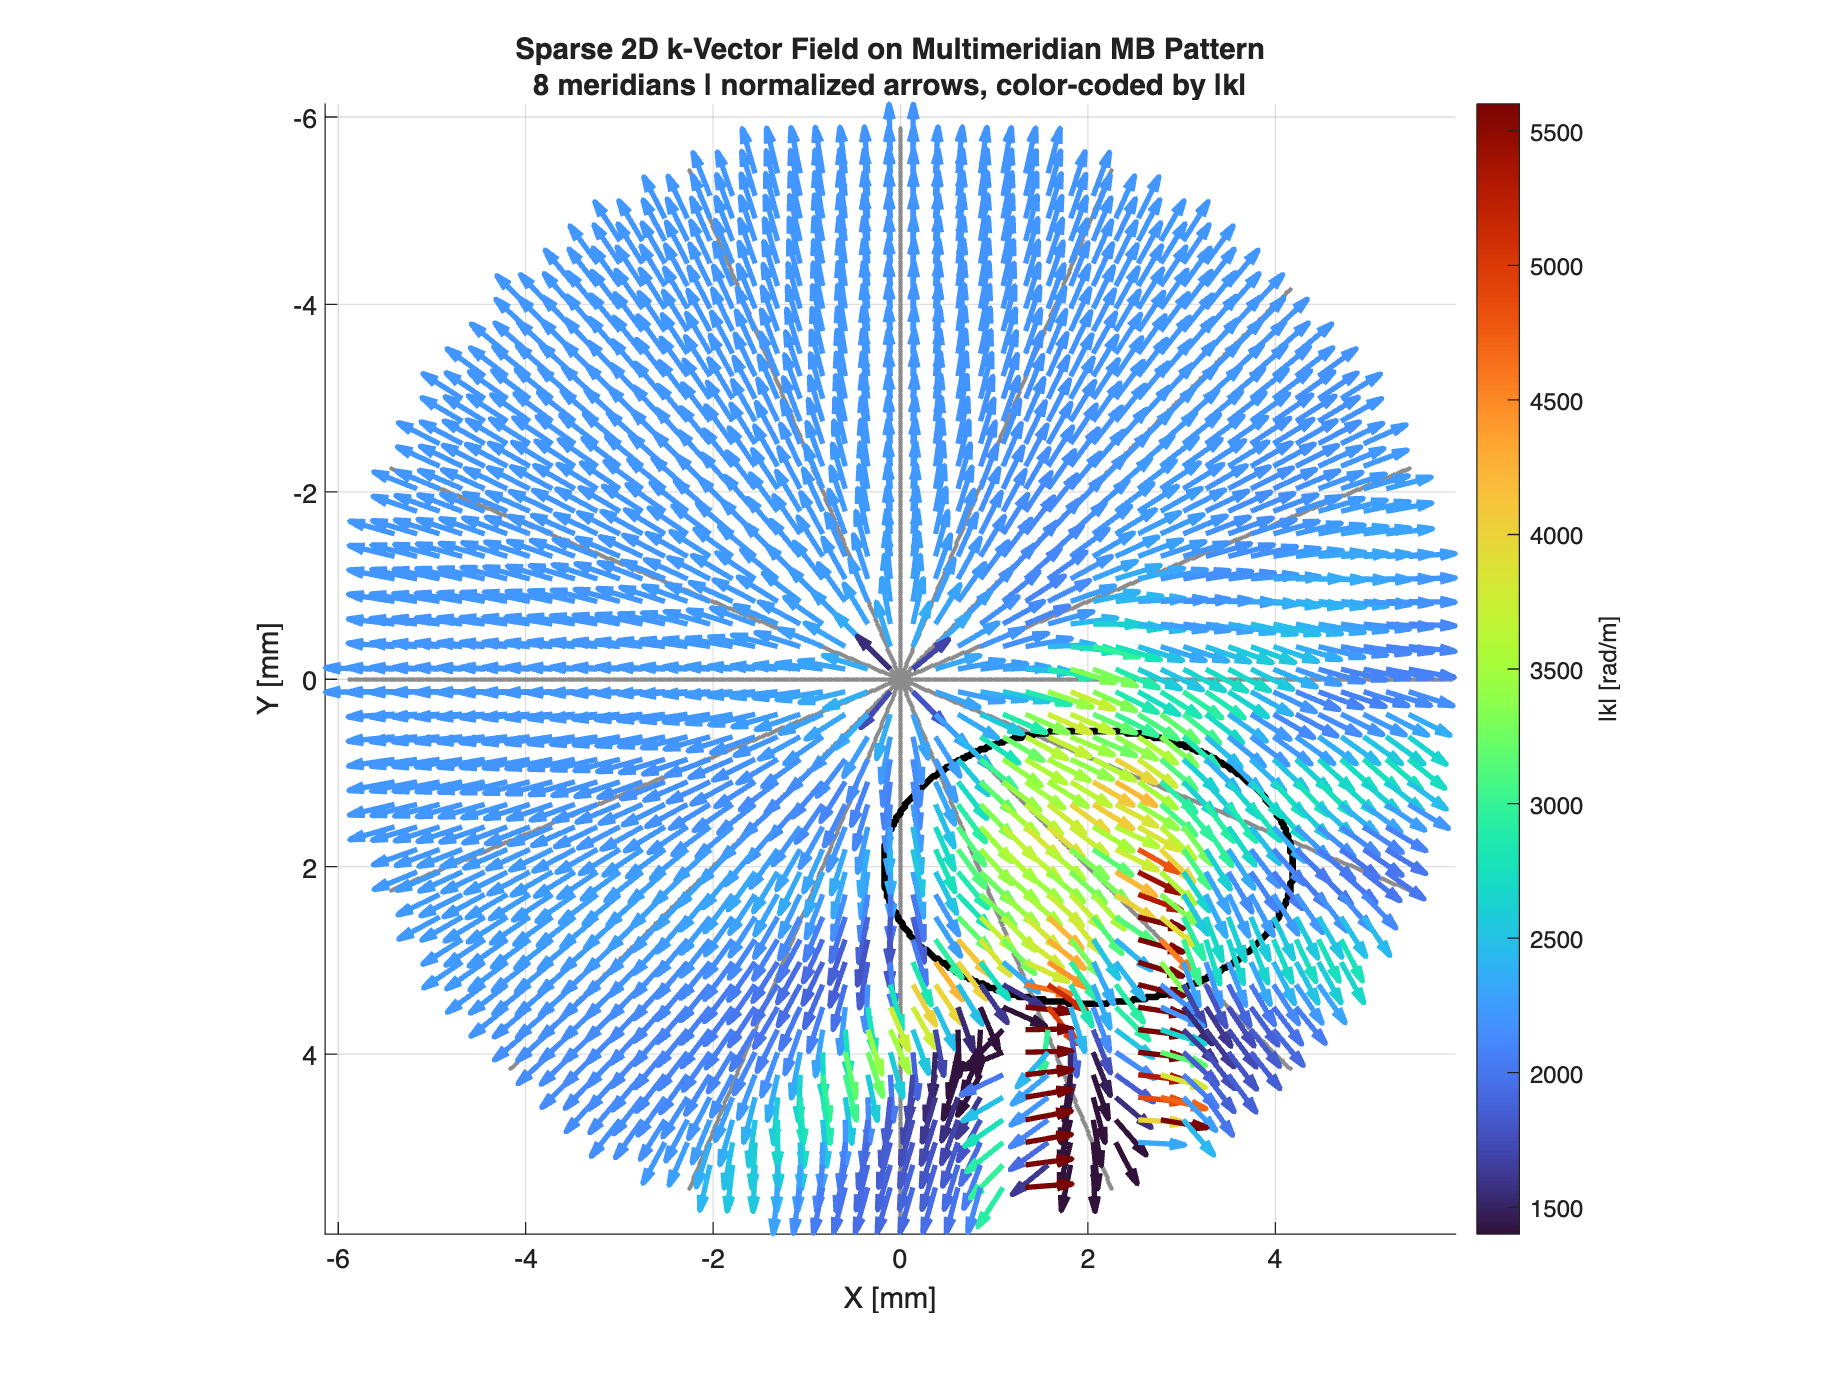

kplot_opts = struct();
kplot_opts.vectorStride = 10;
kplot_opts.vectorScale_mm = 0.5;
kplot_opts.forceOutward = true;
kplot_opts.sourceOrigin_mm = [0 0];
kplot_opts.kClim = [1400 5600]; % [rad/m]

plot_KVectorField_On_MBPattern( ...
    Kx_OGWP, Ky_OGWP, Inc_Mask_Crop_OGWP, ...
    Number_Meridians, Xcrop_mm_OGWP, Ycrop_mm_OGWP, ...
    kplot_opts);

## Definition of Acquisition Vectors from Multimeridian MB Mode Protocol

Based on GalvoFuncOCE function implemented in Keralastic's system (PhS Swept-Source OCT)

### User Parameters/Inputs

nFrames = 1; % Compatibility, same as nClusters
% Ts_OCT = 5e-6;         % [s] A-line period (200 kHz)
% horizontalMin = -6; horizontalMax = 6;
% verticalMin = -6; verticalMax = 6;
% M_repetitions = 200; % kept for compatibility
nAscans = nAscans_per_meridian; % A-lines per meridian
nBscans = Number_Meridians; % number of meridians

% Amplitude of SyncSamples:
% SyncAmp = 1;

% FIFO Buffer for Acquisitions, Limit:
% Max_Buffer = 1800;

% TTL pulse widths (in OCT samples)
ExcPulseWidth = 10;   % excitation TTL width (samples)
AcqPulseWidth = 1;   % acquisition TTL width (samples)

% delay after excitation before scanning starts (and before acquisition train)
startDelay_samples = 0;   % small delay so excitation rising edge leads acquisition/scan, kept for compatibility

% Resolution of the transition turns (NaN gap length to be spline-filled)
% nSyncSamples = 50;     % number of samples to discretize each transition turn

### Generation of Acquisition Vectors

Using the `AcqVectors_SBM` function, we compute the acquisition vectors that correspond with the given user inputs for the SBM protocol:

samplesPerExcPeriod = 57 (T_exc = 0.285 ms)
Total spatial points per frame = 800 (8 meridians x 100 points/meridian)
Built Multimeridian MB waveform timeline: total samples = 199950


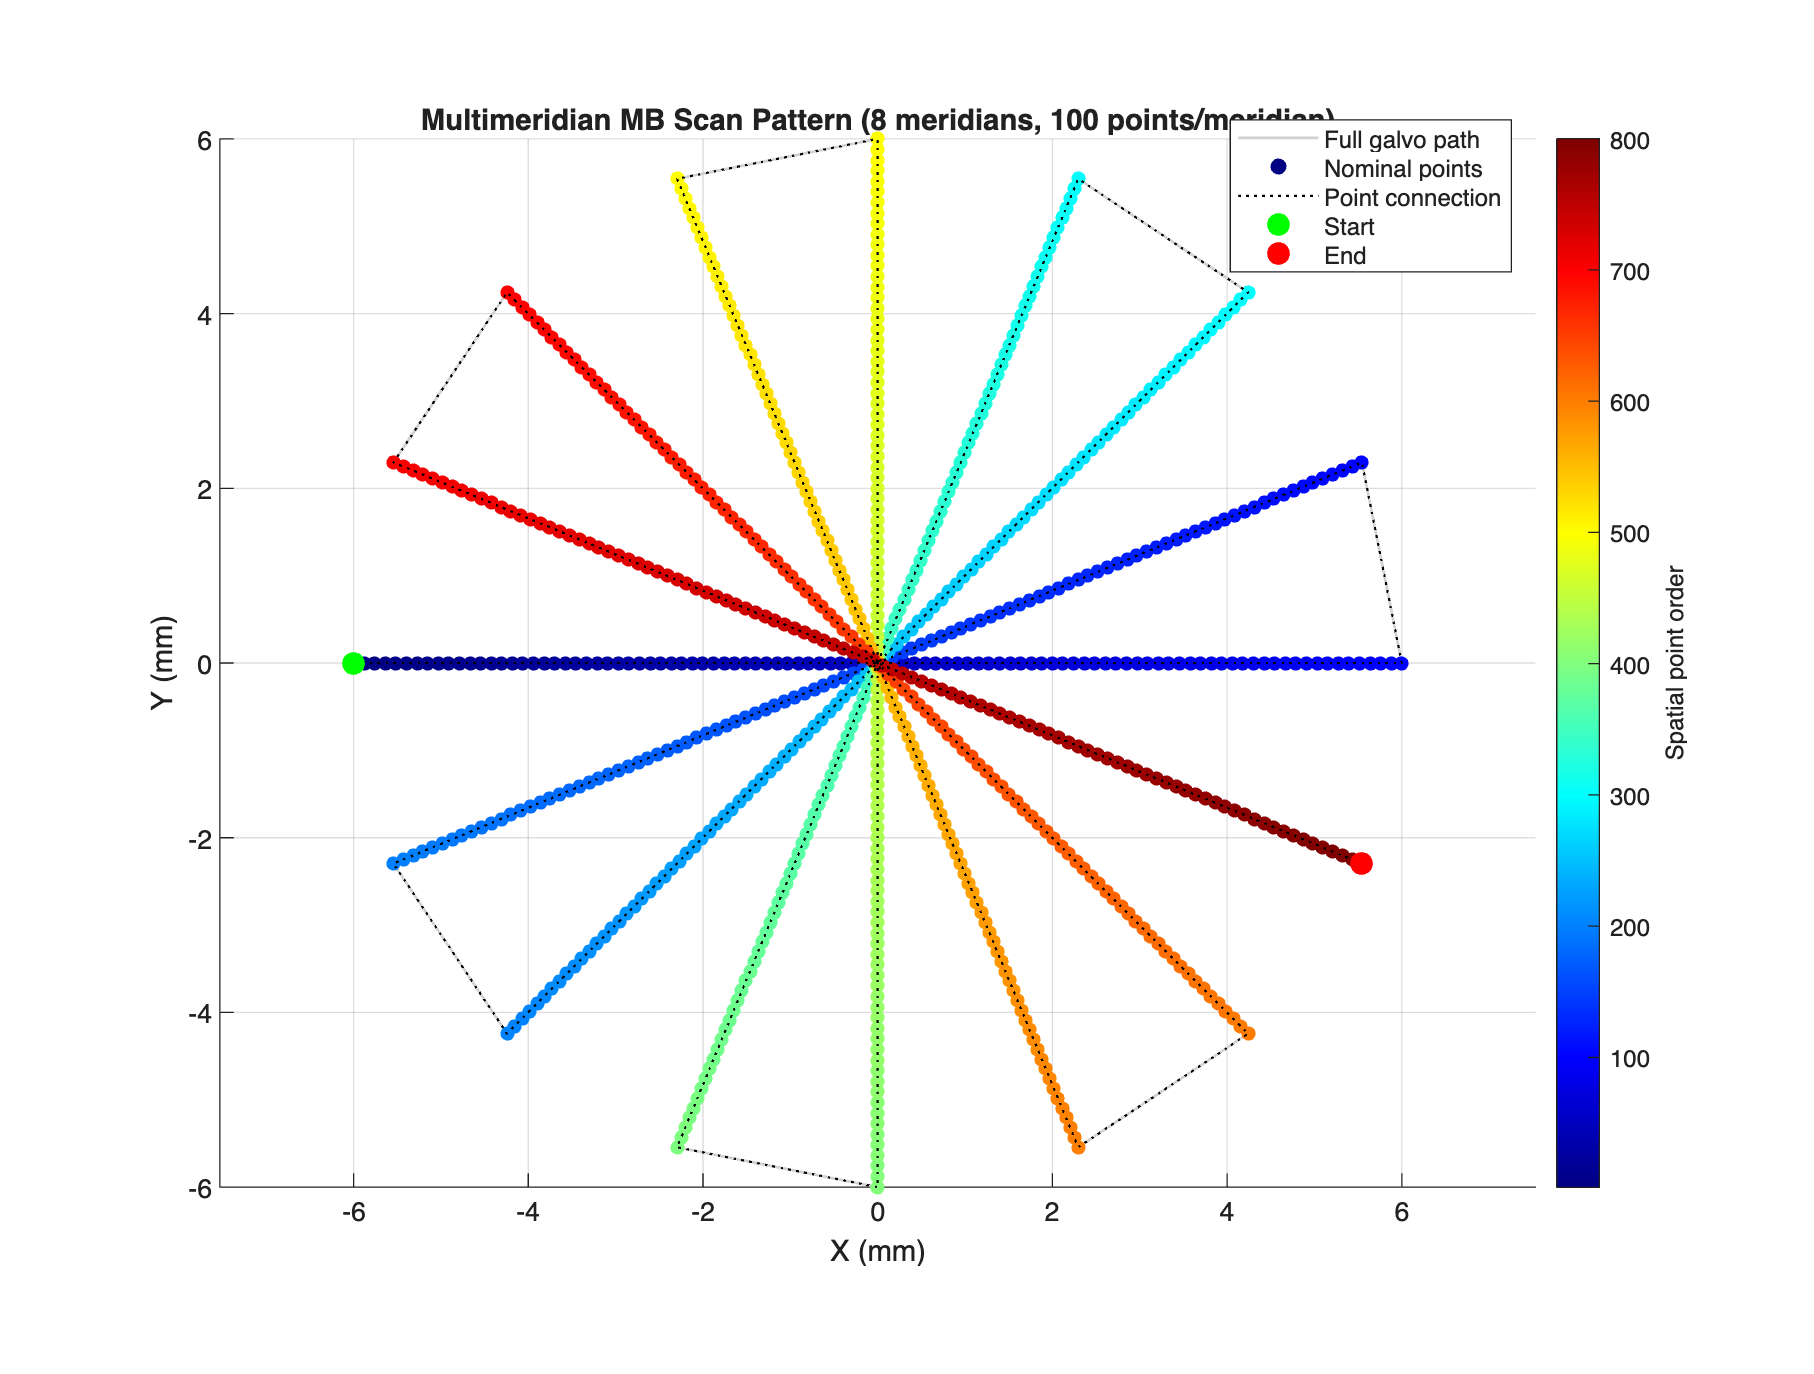

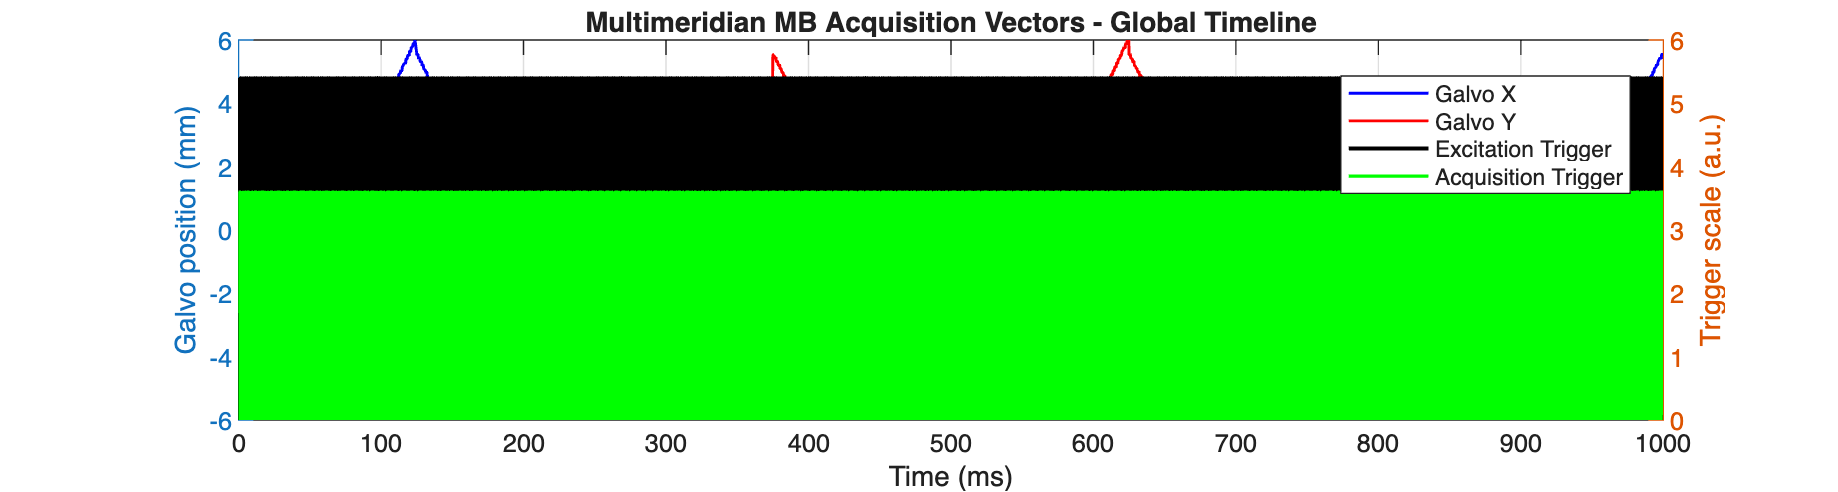

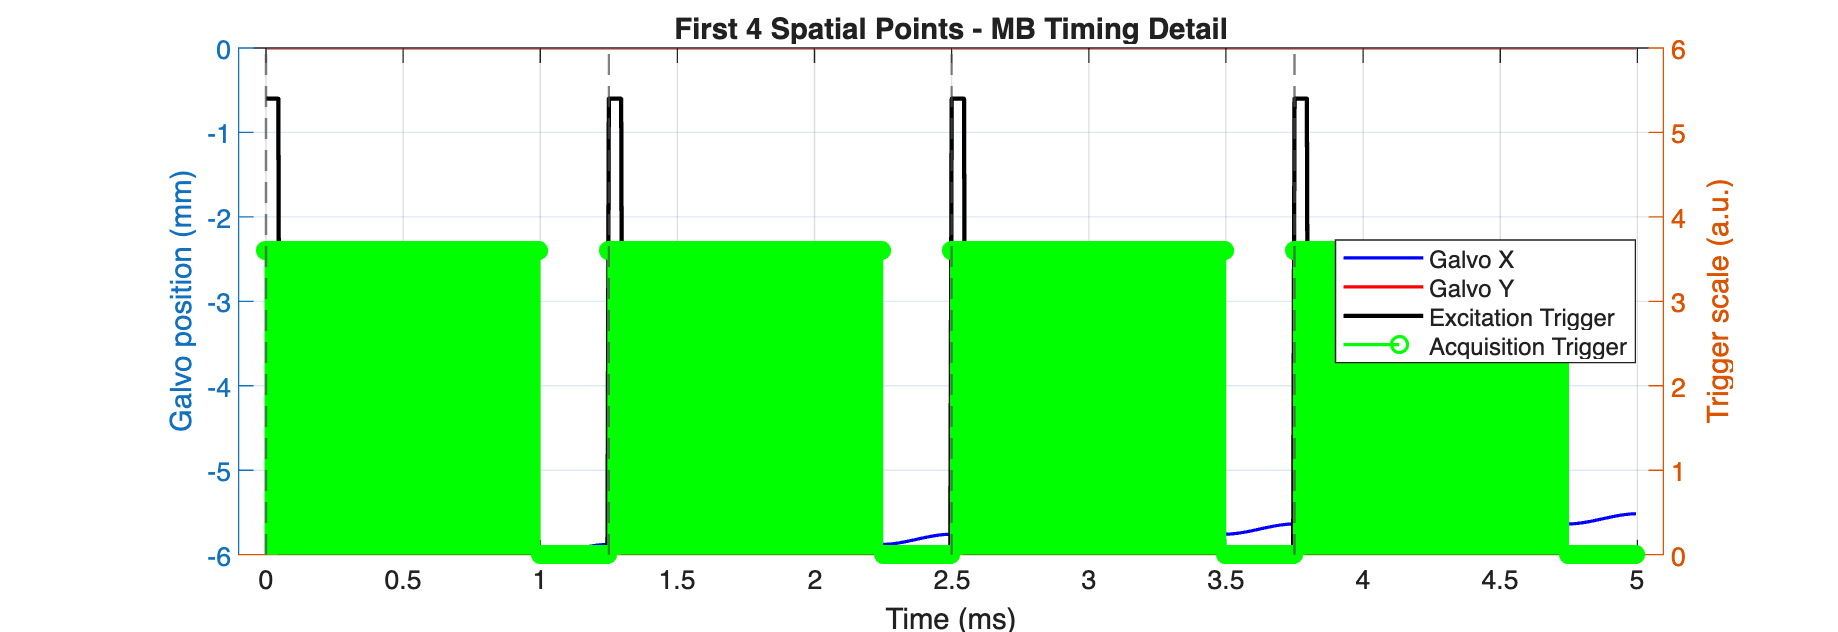

[Exc_Trigger,Acq_Trigger,GalvoX,GalvoY] = AcqVectors_MultimeridianMB(horizontalMin,horizontalMax,verticalMin,...
                                                    verticalMax,nAscans,nBscans,nFrames,...
                                                    startDelay_samples,nSyncSamples,AcqPulseWidth,...
                                                    ExcPulseWidth,T_excitation,Ts_OCT,M_repetitions);

### Quick Manual Diagnostics

Time vector for the acquisition:

t_acqvecs = 0:Ts_OCT:(length(GalvoX)-1)*Ts_OCT;

Control of xlims (in ms) in order to visualize desired region:

xlim_lowbound = 0; % [ms]
xlim_upbound = 165; % [ms]

Galvo X and Galvo Y in the Same Figure:

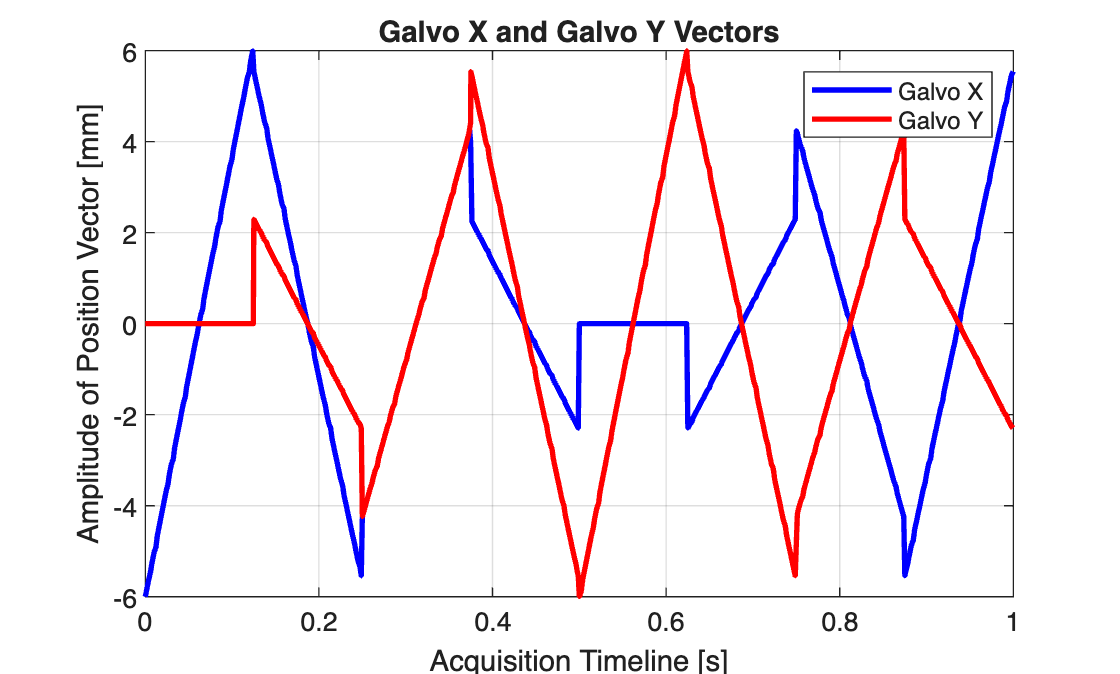

figure,
plot(t_acqvecs,GalvoX,'LineStyle','-','LineWidth',2,'Color','Blue');
hold on;
plot(t_acqvecs,GalvoY,'LineStyle','-','LineWidth',2,'Color','Red');
title("Galvo X and Galvo Y Vectors");
xlabel("Acquisition Timeline [s]");
ylabel("Amplitude of Position Vector [mm]");
legend("Galvo X","Galvo Y");
grid on;

% % From region limited by user input:
% xlim([xlim_lowbound xlim_upbound]*1e-3);

Plot of 4 vectors in tiled layout:

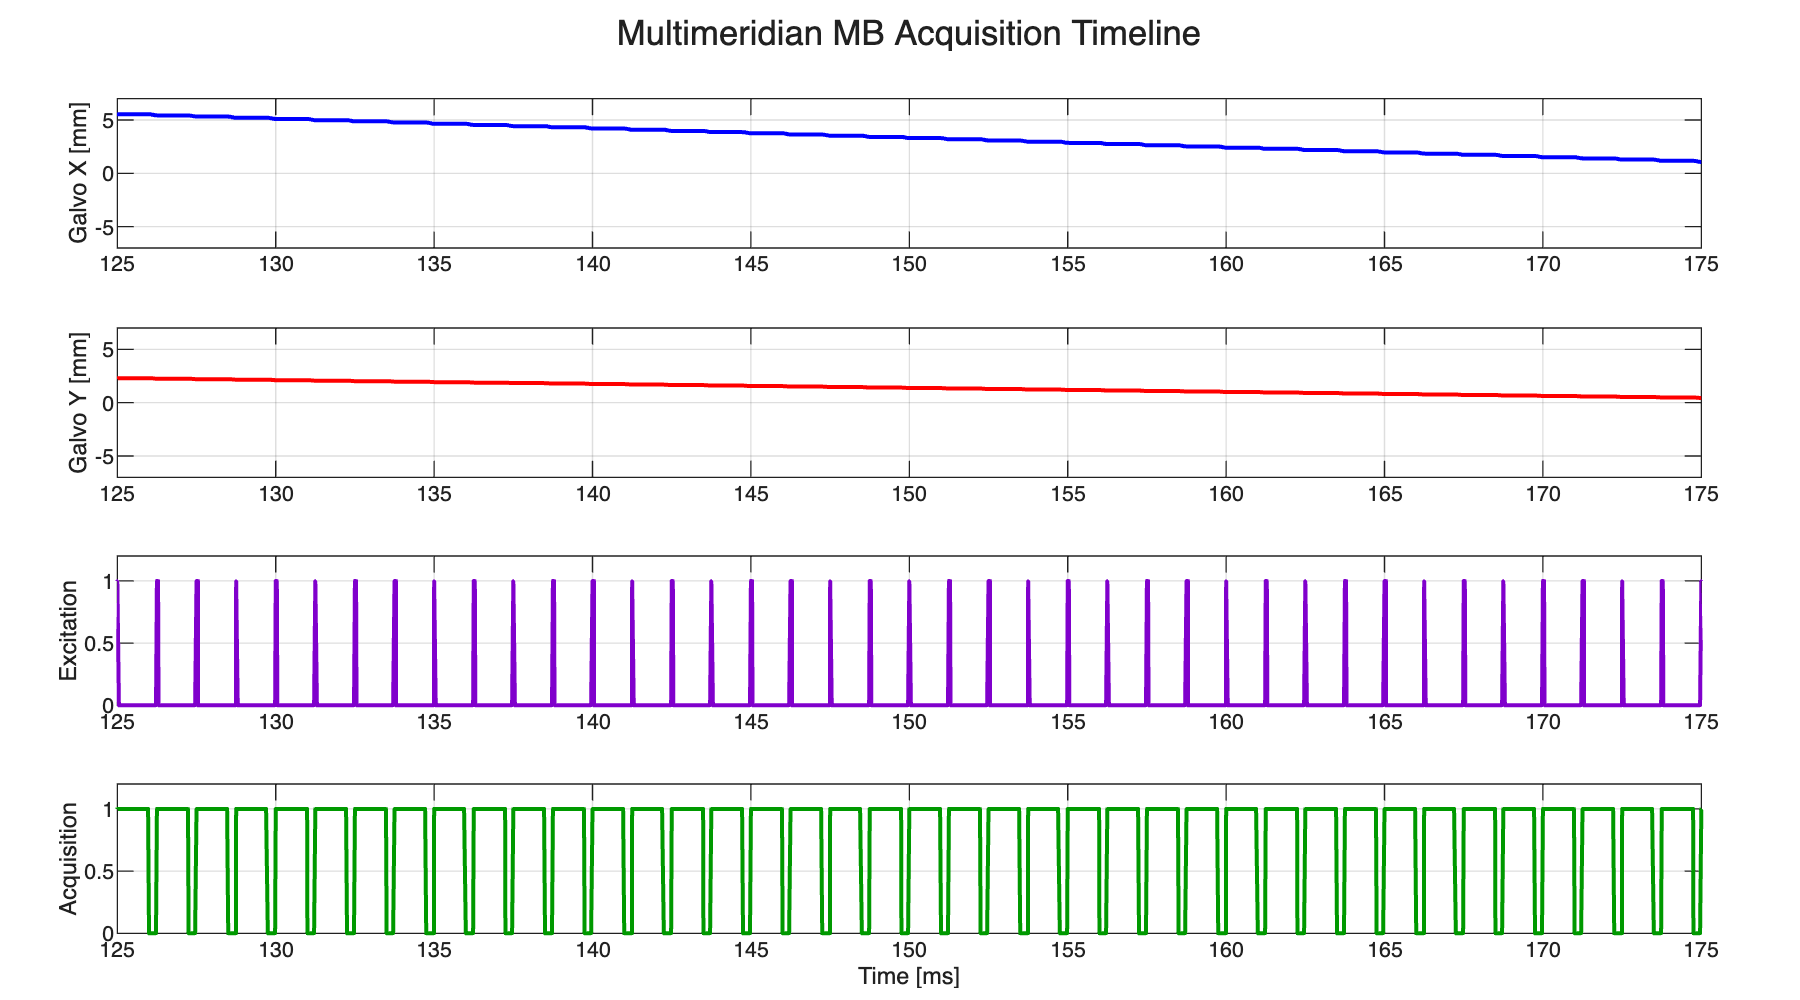

% ===================== INPUT =====================
% [Exc_Trigger,Acq_Trigger,GalvoX,GalvoY] already computed

% Time vector
N = length(GalvoX);
t = (0:N-1) * Ts_OCT * 1e3; % [ms]

% Normalize triggers
Exc_plot = Exc_Trigger / max(Exc_Trigger);
Acq_plot = Acq_Trigger / max(Acq_Trigger);

% ===================== FIGURE =====================
figure('Color','w','Position',[100 100 900 500]);

tiledlayout(4,1,'TileSpacing','compact','Padding','compact');

% ===================== GALVO X =====================
nexttile;
plot(t, GalvoX, 'b', 'LineWidth', 1.5);
ylabel('Galvo X [mm]');
ylim([min(GalvoX)-1 max(GalvoX)+1]);
% xlim([1250 1300]);
xlim_start_t_ms = 125;
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== GALVO Y =====================
nexttile;
plot(t, GalvoY, 'r', 'LineWidth', 1.5);
ylabel('Galvo Y [mm]');
ylim([min(GalvoY)-1 max(GalvoY)+1]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== EXCITATION TRIGGER =====================
nexttile;
plot(t, Exc_plot, 'Color',[0.5 0 0.8], 'LineWidth', 1.5);
ylabel('Excitation');
ylim([0 1.2]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== ACQUISITION TRIGGER =====================
nexttile;
plot(t, Acq_plot, 'Color',[0 0.6 0], 'LineWidth', 1.5);
ylabel('Acquisition');
xlabel('Time [ms]');
ylim([0 1.2]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== GLOBAL =====================
sgtitle('Multimeridian MB Acquisition Timeline');

% Link axes (still useful for zoom consistency)
linkaxes(findall(gcf,'Type','axes'),'x');

## Sampling Simulation

Now that we have our acquisition vectors, let's sample the wave-propagation video in accordance to them. 

### Sampling Obeying Acquisition Vectors

This is the saccadic version of the simulations, so we will include the saccadic modeling parameters as inputs to our simulation engine.

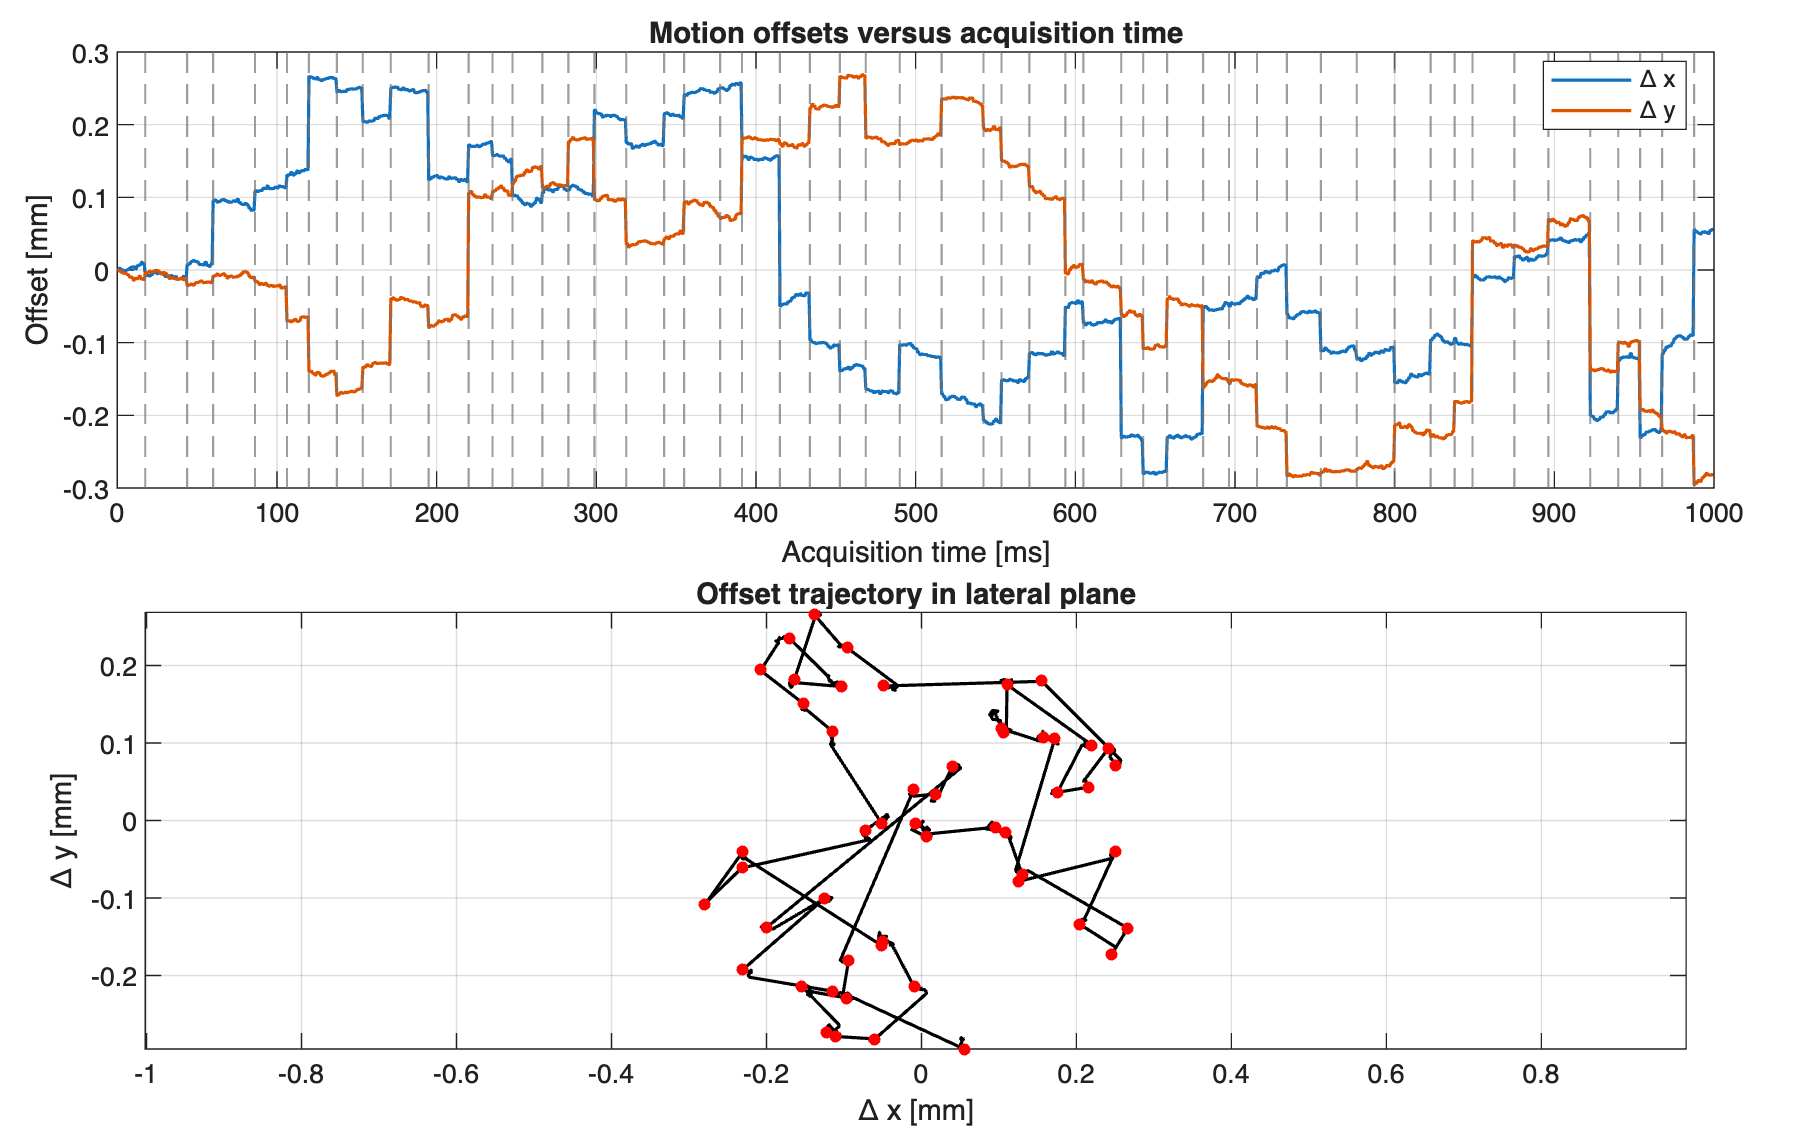


Sampling_fromAcqVecs_Generalized_v2
Framework                  : MB
Motion case                : saccadic
Active acquisition samples : 160000
Samples per sim ensemble   : 250
Number of sim ensembles    : 2
Ensemble cycle             : 2
Spatial_Frames size        : [100  100  200]
Sampled_Frames_2 size      : [100  200    8]
Max |DeltaX| [mm]          : 0.2809
Max |DeltaY| [mm]          : 0.2949
Max radial offset [mm]     : 0.3000
Mean radial offset [mm]    : 0.1939



MotionCase   = 'saccadic';
AcqFramework = 'MB';

%% Saccadic Parameters:
% Create structure and enable it:
SaccadeParams = struct();
SaccadeParams.enable = true;
% Probabilistic and simulation parameters:
SaccadeParams.fixationMinPts = 8;
SaccadeParams.fixationMaxPts = 20;
SaccadeParams.driftSigma_mm = 0.002;
SaccadeParams.ampDistribution = 'gamma';
SaccadeParams.gammaShape      = 2.0;
SaccadeParams.gammaScale_mm   = 0.04;
SaccadeParams.thetaMode      = 'uniform';
SaccadeParams.horizontalBias = 0.7;
SaccadeParams.maxOffset_mm = 0.30;
SaccadeParams.interpMethod = 'linear';
SaccadeParams.rngSeed = 1;
% Diagnostic parameters:
SaccadeParams.makeFigures = true;
% SaccadeParams.makeMotionVideo = true;
SaccadeParams.makeMotionVideo = false;
% SaccadeParams.motionVideoName = 'MB_SaccadeTrajectory_Diagnostics.mp4';

% Sampling:

[Spatial_Frames_Generalized_MB, Meridian_Frames_MB, SamplingInfo_MB] = ...
    Sampling_fromAcqVecs_Generalized( ...
    WaveProp_Vid, x_grid, y_grid, t_grid, ...
    GalvoX, GalvoY, Acq_Trigger, Exc_Trigger, ...
    nFrames, nAscans, nBscans, T_excitation, Ts_OCT, ...
    MotionCase, AcqFramework, ...
    'SamplesPerSimEnsemble', M_repetitions + nSyncSamples, ...
    'InterpMethod', 'linear', ...
    'ExtrapMethod', 'none', ...
    'TemporalDelay_s', 0, ...
    'SaccadeParams', SaccadeParams, ...
    'MakeDiagnostics', true);

### Video of Sampled Frames

Obtain color limits for video

% Set up robust colormap: mean ± 1 sd:
mean_Spatial_Frames_Generalized_MB = mean(reshape(Spatial_Frames_Generalized_MB,1,[]),"omitnan");
std_Spatial_Frames_Generalized_MB = std(reshape(Spatial_Frames_Generalized_MB,1,[]),"omitnan");
clim_low = mean_Spatial_Frames_Generalized_MB - 2*std_Spatial_Frames_Generalized_MB;
clim_high = mean_Spatial_Frames_Generalized_MB + 2*std_Spatial_Frames_Generalized_MB;
clim_robust = min(abs(clim_low),abs(clim_high));

Obtain video:

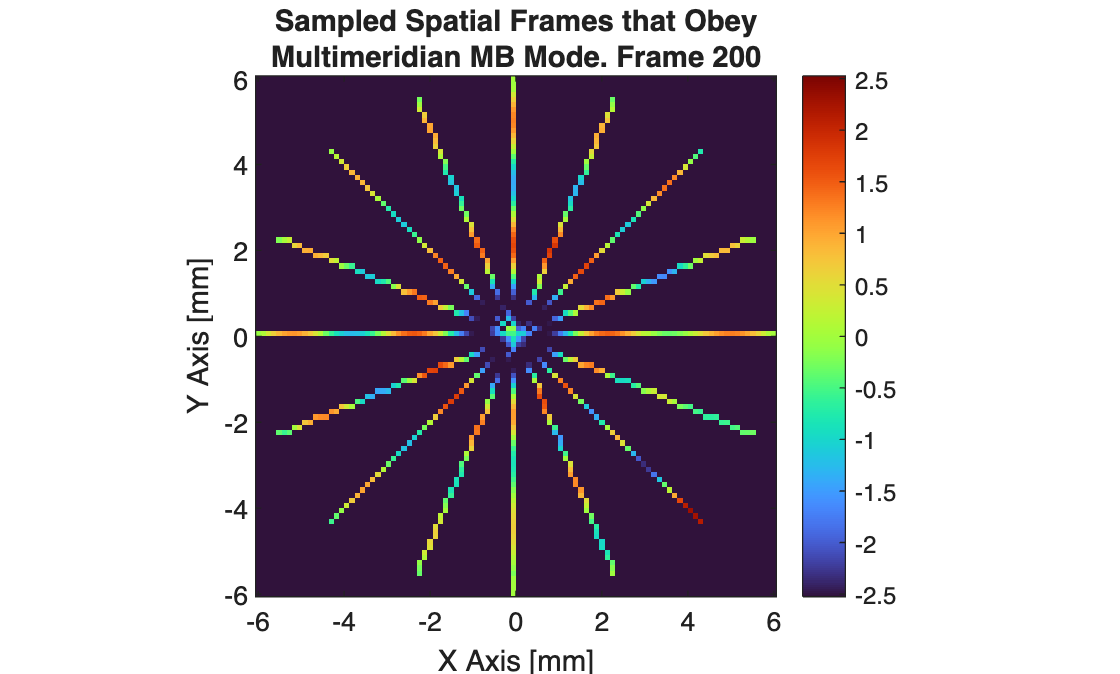

% Get video:
figure,
for i = 1:size(Spatial_Frames_Generalized_MB,3)

    current_frame = flipud(Spatial_Frames_Generalized_MB(:,:,i));
    
    % imagesc(linspace(GalvoX(1),GalvoX(end),nAscans),linspace(GalvoY(1),GalvoY(end),nBscans),current_frame)
    imagesc(linspace(verticalMin,verticalMax,nBscans),linspace(horizontalMin,horizontalMax,nAscans),current_frame)
    axis image; set(gca,'YDir','normal');

    title({"Sampled Spatial Frames that Obey",sprintf("Multimeridian MB Mode. Frame %d",i)});
    xticks(-6:2:6)
    xlabel("X Axis [mm]")
    ylabel("Y Axis [mm]")
    set(gca,'YDir','normal'); axis tight;
    clim([-clim_robust clim_robust])
    colormap("turbo")
    colorbar
    %drawnow
    pause(0.1)
end

### Space-Time map of Sampled Frames from Meridian Frames

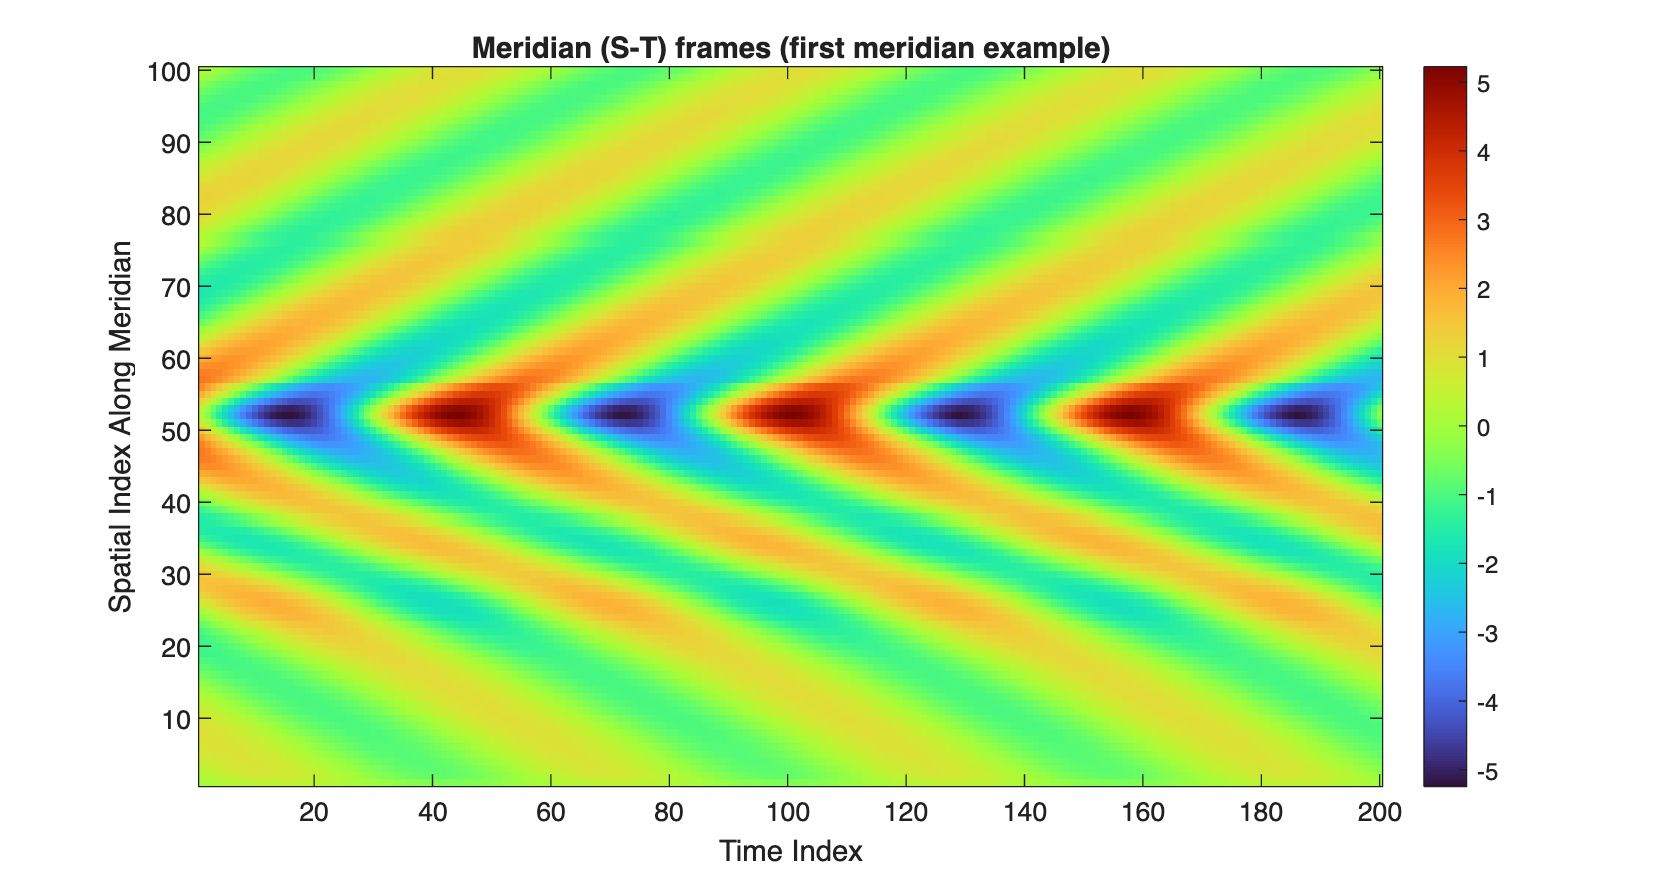

figure('Name','First Meridian S-T Matrix','Units','normalized','Position',[0.18 0.12 0.55 0.45]);
imagesc(Meridian_Frames_MB(:,:,2));
axis xy; colorbar; colormap("turbo");
xlabel('Time Index');
ylabel('Spatial Index Along Meridian');
title('Meridian (S-T) frames (first meridian example)');

## Phase Speed Estimation on Sampled Frames using Interpolation and 2D Phase Gradient

### Preliminaries: Interpolation

Preparing MB movie for 2D Phase Gradient...
Input sparse movie size: [100 x 100 x 200]
Number of originally sampled pixels: 692
Number of pixels inside interpolation hull: 7508
Applying NaN-aware Gaussian smoothing (sigma = 0.80 px)...
Preparation complete.
Output WavePropSim_3DMat size: [100 x 100 x 200]


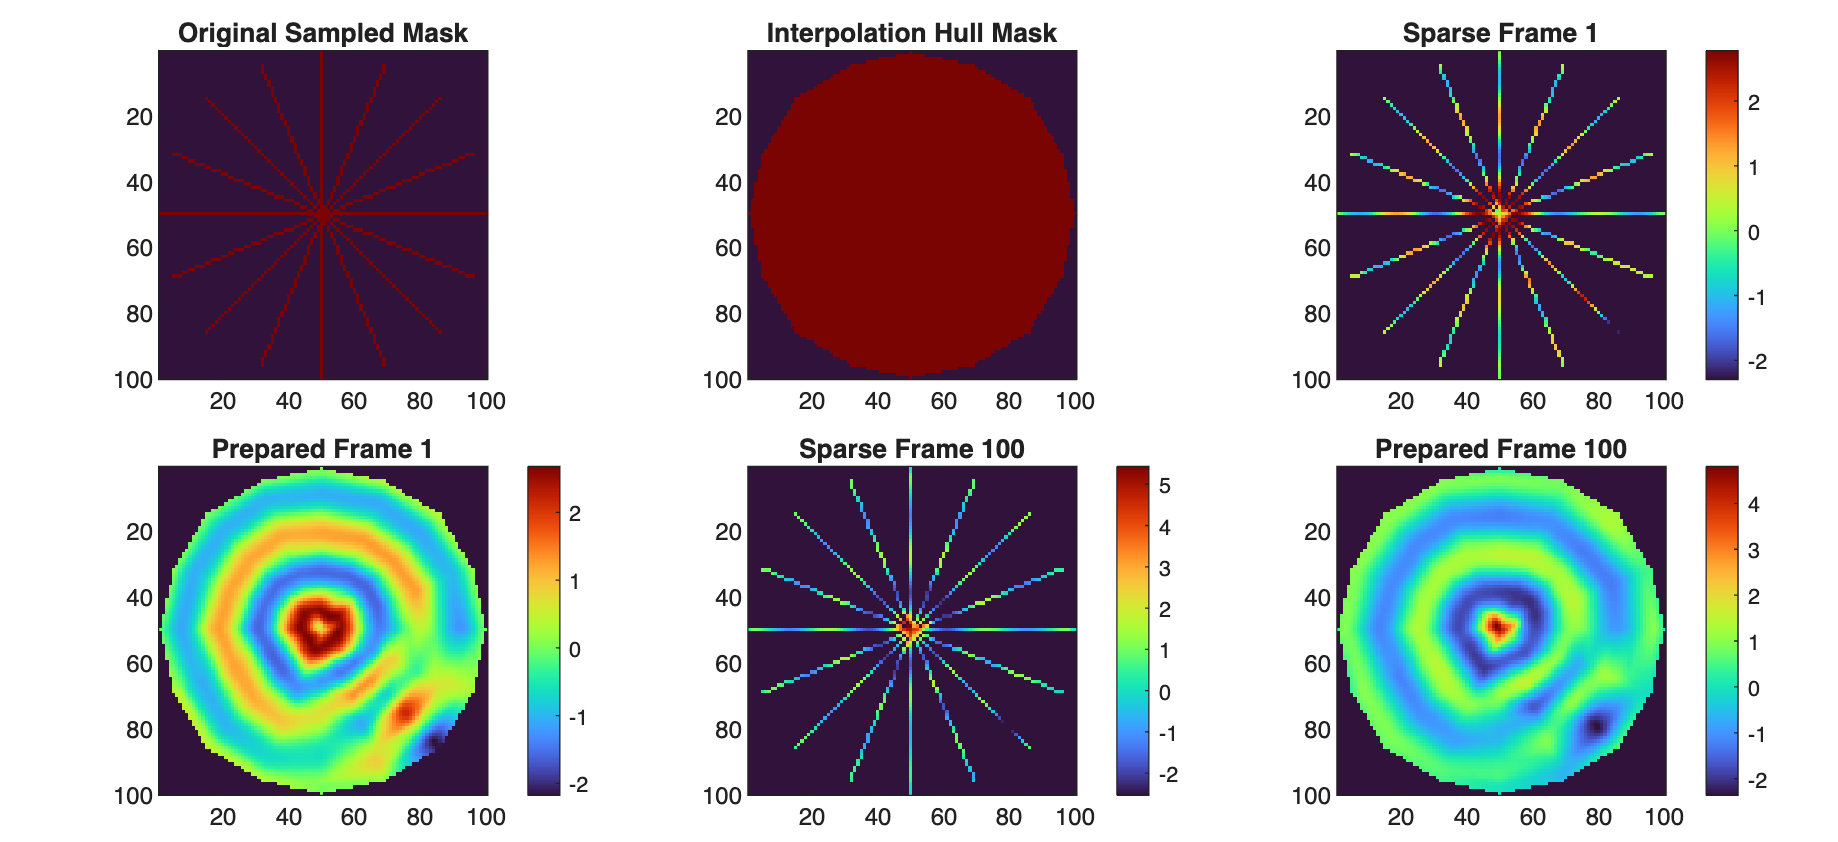

%% Prepare MB movie for 2D Phase Gradient estimation

[WavePropSim_3DMat_MB_Interp, ValidMask_MB, HullMask_MB, InterpOperator_MB] = ...
    Prepare_MB_2DPhaseGradient(Spatial_Frames_Generalized_MB, ...
                                'linearDT', ...      % interpolation method
                                 false, ...          % keep outside hull as NaN
                                true);              % apply light smoothing

#### Visualize prepared frames as video:

Obtain color limits for video

% Set up robust colormap: mean ± 1 sd:
mean_PreppedFrames_MB = mean(reshape(WavePropSim_3DMat_MB_Interp,1,[]),"omitnan");
std_PreppedFrames_MB = std(reshape(WavePropSim_3DMat_MB_Interp,1,[]),"omitnan");
clim_low = mean_PreppedFrames_MB - 2*std_PreppedFrames_MB;
clim_high = mean_PreppedFrames_MB + 2*std_PreppedFrames_MB;
clim_robust = min(abs(clim_low),abs(clim_high));

Obtain video:

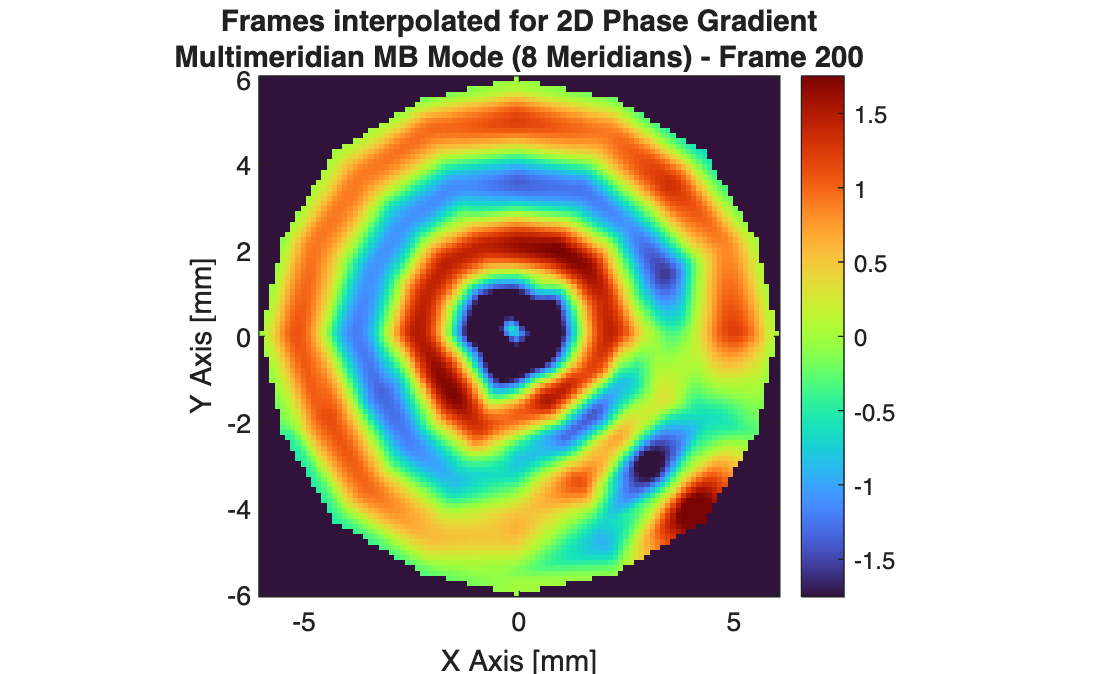

% Get video:
figure,
for i = 1:size(WavePropSim_3DMat_MB_Interp,3)

    current_frame = (flipud(WavePropSim_3DMat_MB_Interp(:,:,i)));
    
    % imagesc(linspace(GalvoX(1),GalvoX(end),nAscans),linspace(GalvoY(1),GalvoY(end),nBscans),current_frame)
    imagesc(linspace(verticalMin,verticalMax,nBscans),linspace(horizontalMin,horizontalMax,nAscans),current_frame)
    axis image; set(gca,'YDir','normal');

    title({"Frames interpolated for 2D Phase Gradient",...
        sprintf("Multimeridian MB Mode (%d Meridians) - Frame %d",nBscans,i)})
    xlabel("X Axis [mm]")
    ylabel("Y Axis [mm]")
    set(gca,'YDir','normal'); axis tight;
    clim([-clim_robust clim_robust])
    % clim([-2.2 4.2])
    colormap("turbo")
    colorbar
    %drawnow
    pause(0.1)
end

### Speed Estimation using 2D PG Approach

PhaseGradient2D_FromSims_v3()
Phase-gradient estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=5e-06 s (fs=200000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=19 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)


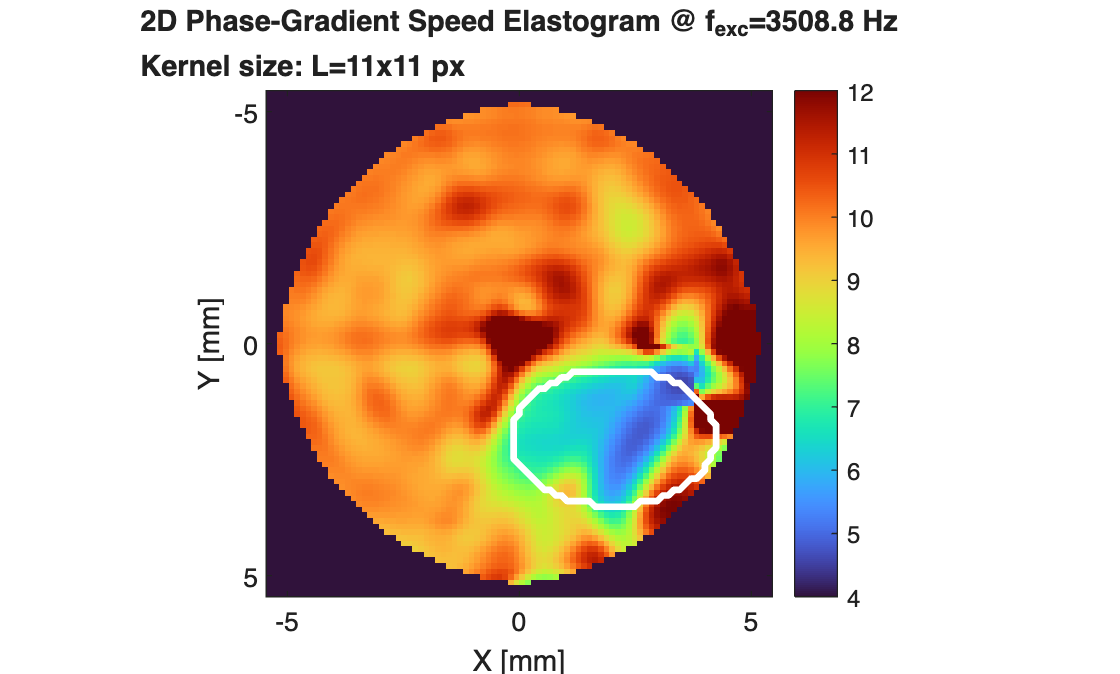

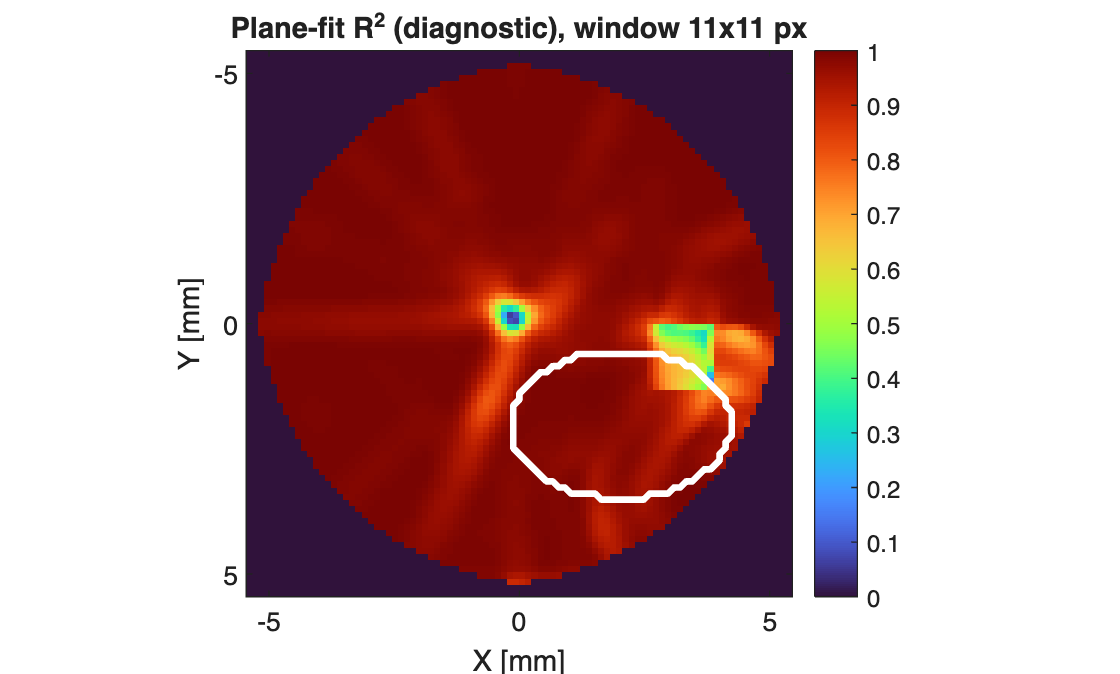

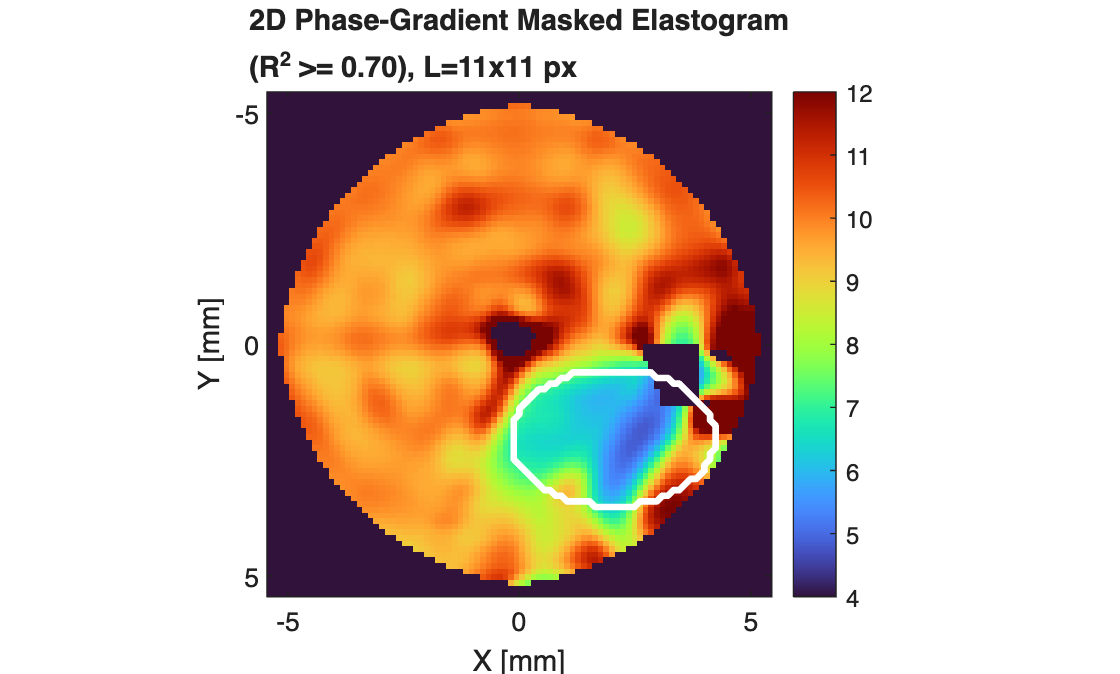

% kernel_size = 11; % L x L window for estimation
% applyTemporalWindow = true;
% % Color limits for 2D PG estimation:
% clim_limits_2DPG = [4 12];

% Downsample Inclusion Mask
Inc_Mask_ReducedMBGrid = imresize(Inc_Mask, size(WavePropSim_3DMat_MB_Interp, 1:2)); % Resize to match the interpolated frames
Bkg_Mask_ReducedMBGrid = imresize(Bkg_Mask, size(WavePropSim_3DMat_MB_Interp, 1:2)); % Resize to match the interpolated frames

% Run 2D Phase Gradient on interpolated MB movie
[Elastogram_MB_2DPG, R2_map_MB_2DPG, Elastogram_Masked_MB_2DPG, ...
 Xcrop_mm_MB_2DPG, Ycrop_mm_MB_2DPG, Complex_Field_Vz_MB_2DPG, ...
 Inc_Mask_Crop_MB_2DPG, Bkg_Mask_Crop_MB_2DPG, Kx_MB_2DPG, Ky_MB_2DPG, Kmag_MB_2DPG] = ...
    PhaseGradient2D_FromSims_v3( ...
        WavePropSim_3DMat_MB_Interp, Inc_Mask_ReducedMBGrid, Bkg_Mask_ReducedMBGrid, ...
        kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        applyTemporalWindow, clim_limits_2DPG);

### Speed Estimation using Regularized 2D PG-TV Approach

#### Explanation of Regularized Phase Gradients with Total Variation Regularization

The conventional 2D Phase Gradient (PG) estimator computes the local wave-number magnitude from the spatial phase gradients of the complex harmonic field. Although the estimator is robust under dense and noise-free sampling conditions, the resulting wave-number maps may contain local fluctuations caused by interpolation artifacts, sparse spatial sampling, motion corruption, or phase-unwrapping errors. To improve the spatial consistency of the estimated wave-number field, a Total Variation (TV) regularization step can be introduced after the phase-gradient estimation.

First, the local wave-number magnitude is computed from the estimated Cartesian phase-gradient components:


$$k(x,y)=\sqrt{k_x(x,y)^2+k_y(x,y)^2}$$


The TV regularization problem is then formulated as the minimization of a cost functional composed of a quadratic data-fidelity term and a Total Variation penalty:


$$k_{TV}=\underset{k}{\text{arg\,min}}\;\frac{1}{2}\left\|k-k_{raw}\right\|_2^2+\mu\,TV(k)$$


where $k_{raw}$ denotes the wave-number magnitude obtained from the conventional phase-gradient estimator, $\mu$ is the regularization parameter controlling the amount of smoothing, and TV(k) represents the total variation of the wave-number field.

For a two-dimensional elastogram, the isotropic Total Variation is defined as:


$$TV(k)=\sum_{i,j}\sqrt{\left(\frac{\partial k}{\partial x}\right)_{i,j}^{2}+\left(\frac{\partial k}{\partial y}\right)_{i,j}^{2}}$$


This regularization promotes piecewise-smooth wave-number maps while preserving sharp transitions associated with biomechanical boundaries. Unlike conventional low-pass filtering, the TV penalty suppresses high-frequency fluctuations without excessively blurring localized stiffness variations.

After obtaining the regularized wave-number map $k_{TV}$, the local phase speed is recovered using the standard wave relationship


$$c_{TV}(x,y)=\frac{\omega_0}{k_{TV}(x,y)}$$


where $\omega_0=2\pi f_{exc}$ is the angular excitation frequency. The resulting PG-TV elastogram therefore retains the spatial resolution of the original phase-gradient estimator while improving robustness against local estimation noise and interpolation artifacts.

#### Computation of 2D PG-TV

PhaseGradient2D_TV_FromSims()
PG-TV estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=5e-06 s (fs=200000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=19 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)
TV mu = 250
TV iterations = 500
R2 threshold = 0.70
Valid TV pixels = 65.15 %


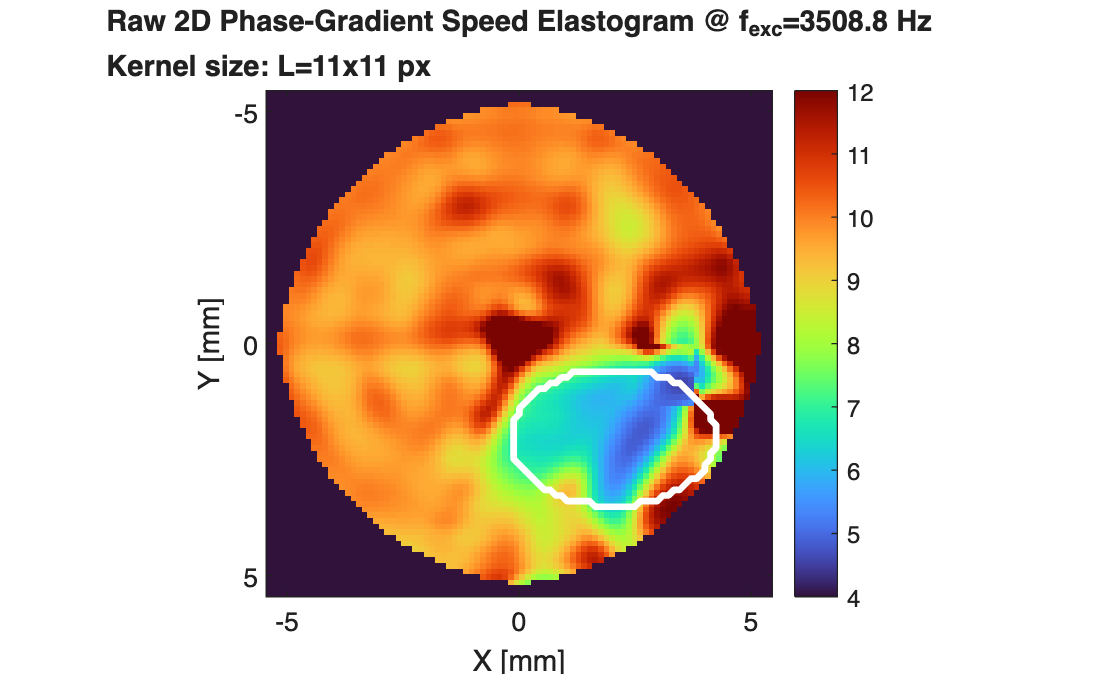

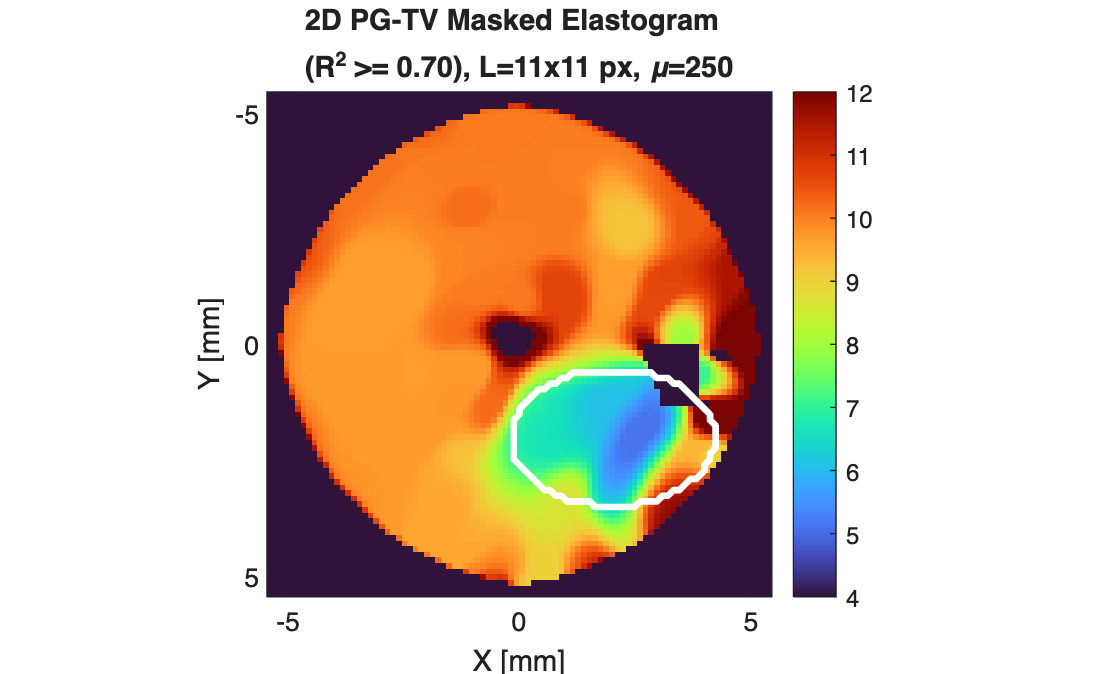

% kernel_size = 11;
% applyTemporalWindow = true;
clim_limits_PGTV = [4 12];

[Elastogram_MB_2DPG_TV, R2_map_MB_2DPG_TV, Elastogram_Masked_MB_2DPG_TV, ...
 Xcrop_mm_MB_2DPG_TV, Ycrop_mm_MB_2DPG_TV, Complex_Field_Vz_MB_2DPG_TV, ...
 Inc_Mask_Crop_MB_2DPG_TV, Bkg_Mask_Crop_MB_2DPG_TV, Kx_MB_2DPG_TV, Ky_MB_2DPG_TV, Kmag_MB_2DPG_TV, ...
 Kmag_TV_MB_2DPG_TV, Elastogram_raw_MB_2DPG_TV, TVInfo_MB_2DPG_TV] = ...
    PhaseGradient2D_TV_FromSims( ...
        WavePropSim_3DMat_MB_Interp, ...
        Inc_Mask_ReducedMBGrid, Bkg_Mask_ReducedMBGrid,...
        kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        applyTemporalWindow, clim_limits_PGTV, ...
        'MuTV', 250, ...
        'TVIterations', 500, ...
        'TVTau', 0.25, ...
        'TVSigma', 0.25, ...
        'TVTheta', 1.0, ...
        'MinK', 500, ...
        'MaxK', 8000, ...
        'R2Threshold', 0.70, ...
        'DisplayFigures', true, ...
        'Verbose', true);

## Metrics Computation using Interpolation and 2D Phase Gradient

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_2DPG, Ea_Inc_2DPG, Ea_Global_2DPG, Ea_Map_2DPG, Ea_Stats_2DPG] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap,  Inc_Mask, Bkg_Mask, Elastogram_Masked_MB_2DPG);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 9.9308 m/s | c_GT_mode = 10.0000 m/s | Ea = 0.692 % | N = 4207 pixels
Inclusion:
  c_hat_mean = 6.4593 m/s | c_GT_mode = 6.0000 m/s | Ea = 7.655 % | N = 547 pixels
Global:
  Ea_Global = 4.173 %



Show $E_a$ map:

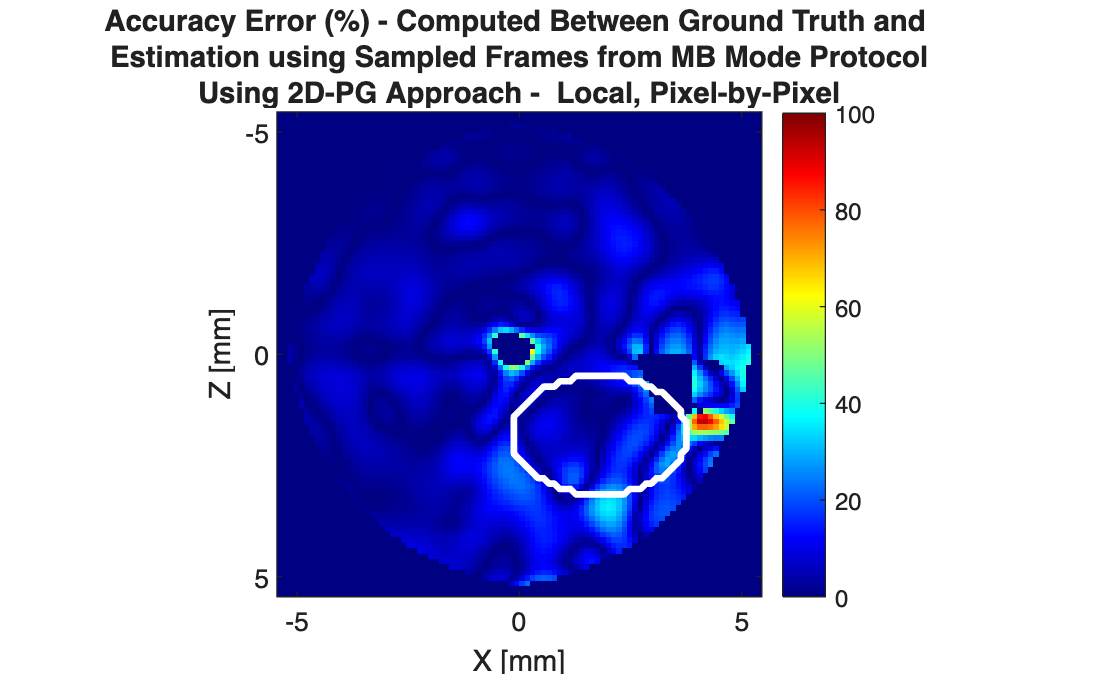

figure, colormap("jet")
imagesc(Xcrop_mm_MB_2DPG, Ycrop_mm_MB_2DPG,Ea_Map_2DPG), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using 2D-PG Approach -  Local, Pixel-by-Pixel"
      });
hold on
Inc_Mask_Ea_2DPG = imresize(logical(Inc_Mask), size(Ea_Map_2DPG), 'nearest');
contour(Xcrop_mm_MB_2DPG, Ycrop_mm_MB_2DPG, double(Inc_Mask_Ea_2DPG), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_2DPG, CNR_ROI_Masks_2DPG, CNR_Stats_2DPG] = Compute_CNR_Masks( ...
    Elastogram_Masked_MB_2DPG, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 9.9308 m/s | std = 0.8888 m/s | N = 4207 pixels
Inclusion : mean = 6.4593 m/s | std = 1.0167 m/s | N = 547 pixels
CNR (Inclusion vs Background) = 3.6356



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_p$** is better**

[Ep_Bkg_2DPG, Ep_Inc_2DPG, Ep_Global_2DPG, Ep_ROI_Masks_2DPG, Ep_Stats_2DPG] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_MB_2DPG, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 8.950 % | mean = 9.9308 m/s | std = 0.8888 m/s | N = 4207 pixels
Inclusion  Ep = 15.739 % | mean = 6.4593 m/s | std = 1.0167 m/s | N = 547 pixels
Global     Ep = 15.004 % | mean = 9.5314 m/s | std = 1.4301 m/s | N = 4754 pixels



## Metrics Computation using Interpolation and 2D PG-TV

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_2DPG_TV, Ea_Inc_2DPG_TV, Ea_Global_2DPG_TV, Ea_Map_2DPG_TV, Ea_Stats_2DPG_TV] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap,  Inc_Mask, Bkg_Mask, Elastogram_Masked_MB_2DPG_TV);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 9.9973 m/s | c_GT_mode = 10.0000 m/s | Ea = 0.027 % | N = 4207 pixels
Inclusion:
  c_hat_mean = 6.5076 m/s | c_GT_mode = 6.0000 m/s | Ea = 8.459 % | N = 547 pixels
Global:
  Ea_Global = 4.243 %



Show $E_a$ map:

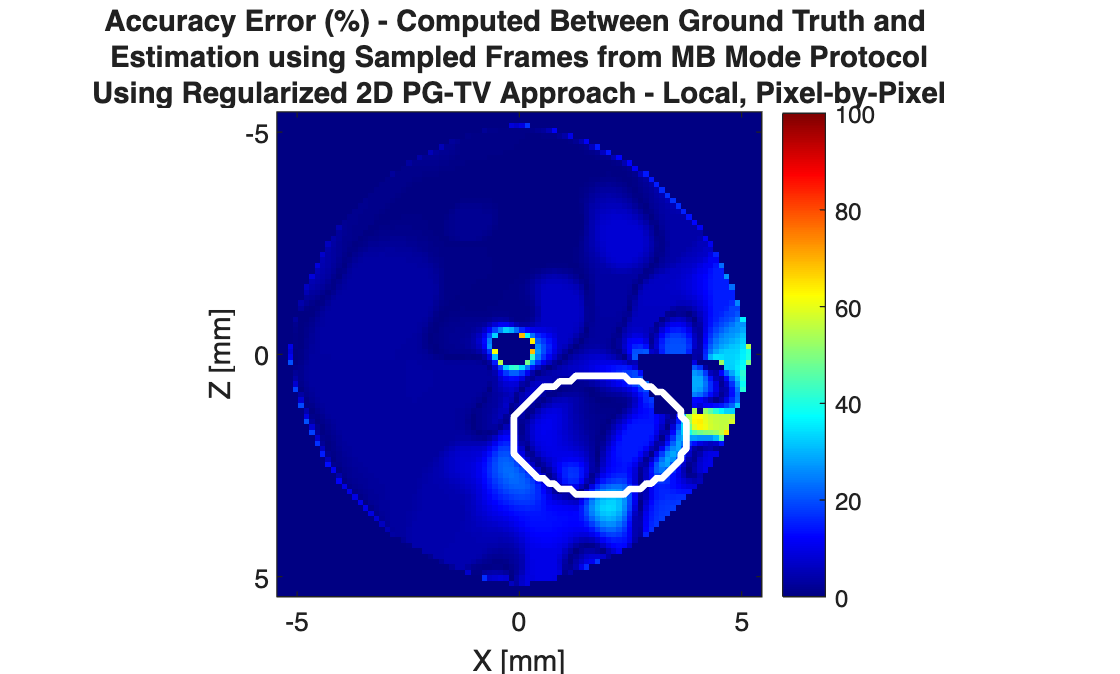

figure, colormap("jet")
imagesc(Xcrop_mm_MB_2DPG_TV, Ycrop_mm_MB_2DPG_TV,Ea_Map_2DPG_TV), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using Regularized 2D PG-TV Approach - Local, Pixel-by-Pixel"
    });
hold on
Inc_Mask_Ea_2DPG_TV = imresize(logical(Inc_Mask), size(Ea_Map_2DPG_TV), 'nearest');
contour(Xcrop_mm_MB_2DPG_TV, Ycrop_mm_MB_2DPG_TV, double(Inc_Mask_Ea_2DPG_TV), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_2DPG_TV, CNR_ROI_Masks_2DPG_TV, CNR_Stats_2DPG_TV] = Compute_CNR_Masks( ...
    Elastogram_Masked_MB_2DPG_TV, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 9.9973 m/s | std = 0.8286 m/s | N = 4207 pixels
Inclusion : mean = 6.5076 m/s | std = 0.9638 m/s | N = 547 pixels
CNR (Inclusion vs Background) = 3.8828



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_p$** is better**

[Ep_Bkg_2DPG_TV, Ep_Inc_2DPG_TV, Ep_Global_2DPG_TV, Ep_ROI_Masks_2DPG_TV, Ep_Stats_2DPG_TV] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_MB_2DPG_TV, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 8.289 % | mean = 9.9973 m/s | std = 0.8286 m/s | N = 4207 pixels
Inclusion  Ep = 14.810 % | mean = 6.5076 m/s | std = 0.9638 m/s | N = 547 pixels
Global     Ep = 14.570 % | mean = 9.5958 m/s | std = 1.3981 m/s | N = 4754 pixels



## Phase Speed Estimation using 1D Phase Gradient Along Meridians

Estimation along meridians:


PhaseGradient_1D_AlongMeridians_MBMode_v3()
Input Meridian_Frames size: [100 x 200 x 8]
f_exc = 3508.77 Hz, omega0 = 22046.26 rad/s, Ts_OCT = 5e-06 s, fs = 200000.00 Hz
Output reduced MB elastogram grid: [100 x 100]
Reconstructed MB acquisition geometry using reduced MB grid.
Nearest FFT bin: kpos = 19 -> f_bin = 3515.62 Hz, error = 6.85 Hz
Valid meridian estimates projected to en face: 720


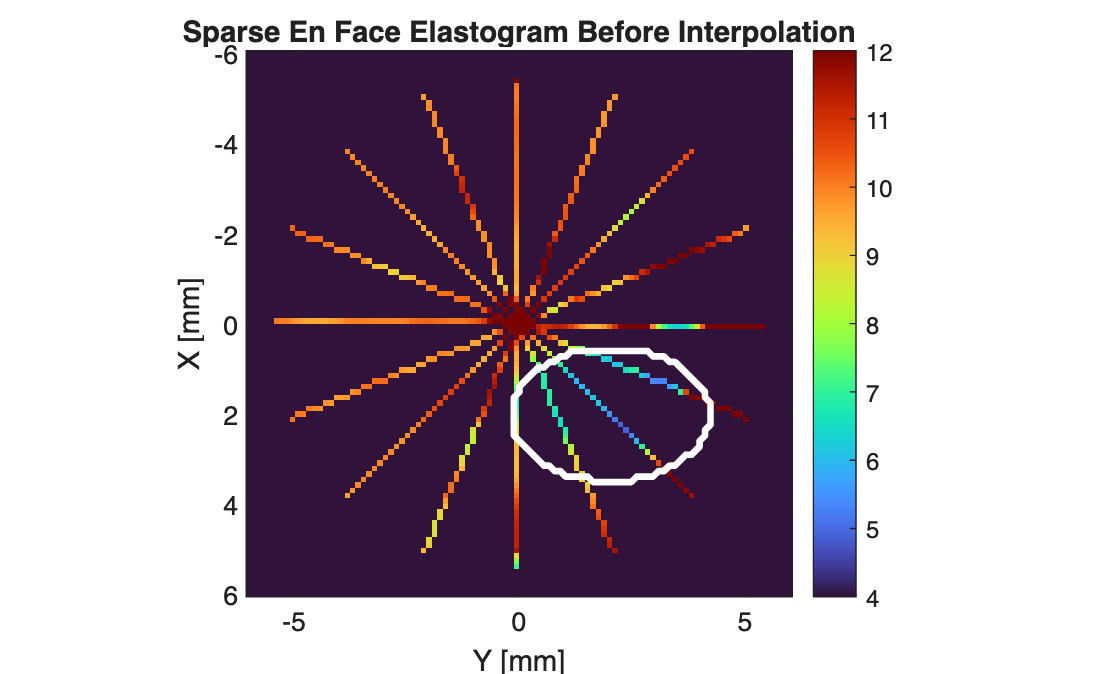

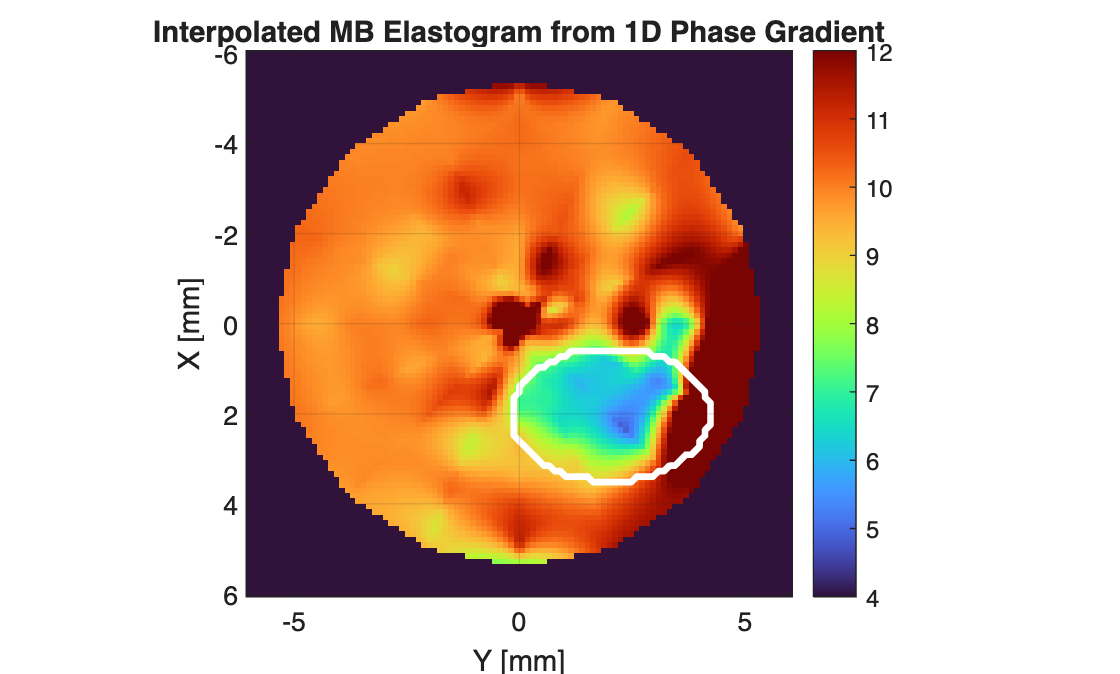

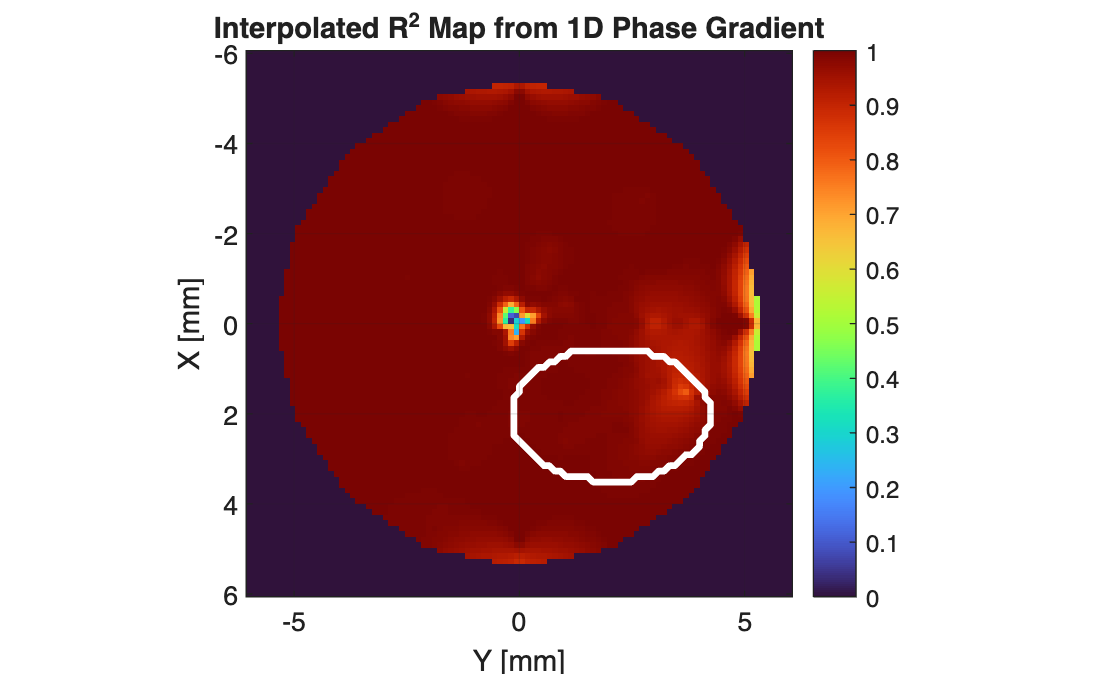

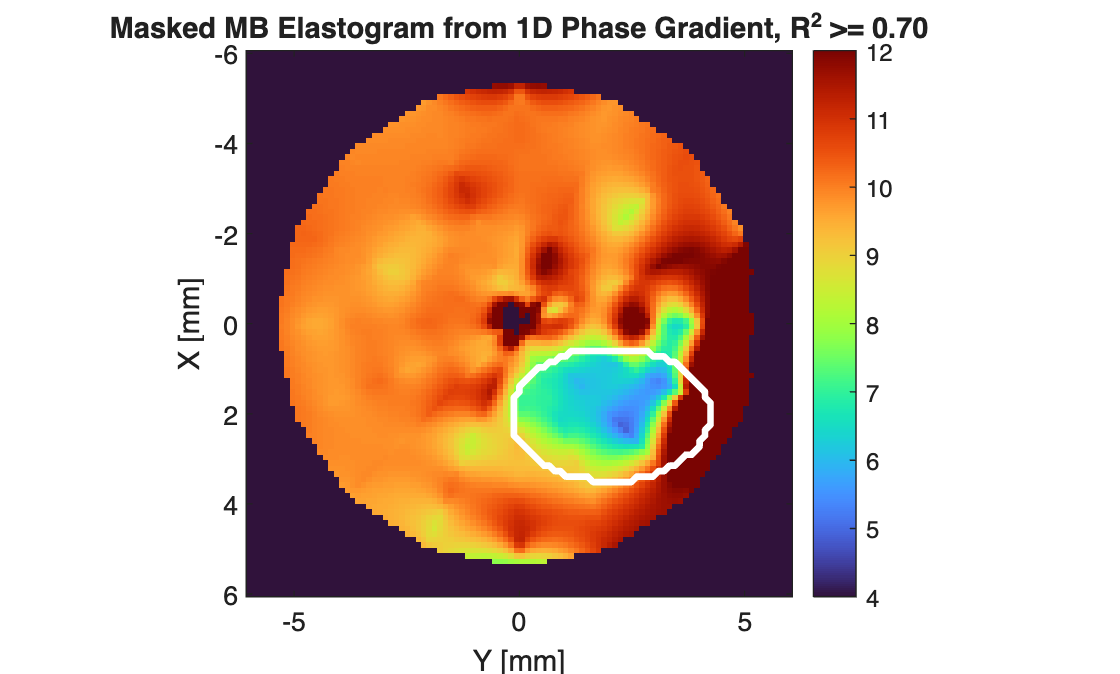

[Elastogram_MB_1DPG,R2_map_MB_1DPG,Elastogram_Masked_MB_1DPG,Xgrid_mm_MB_1DPG,Ygrid_mm_MB_1DPG,SparseElastogram_MB_1DPG,Inc_Mask_MB_1DPG,KVectorField_MB_1DPG] = ...
    PhaseGradient_1D_AlongMeridians_MBMode_v3( ...
        Meridian_Frames_MB, Inc_Mask, kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax);

### Speed Estimation using Regularized 1D PG-TV Approach (Applying TV after Interpolation)


PhaseGradient_1D_AlongMeridians_Regularized_TV()
Input Meridian_Frames size: [100 x 200 x 8]
f_exc = 3508.77 Hz, omega0 = 22046.26 rad/s, Ts_OCT = 5e-06 s, fs = 200000.00 Hz
Output reduced MB elastogram grid: [100 x 100]
Reconstructed MB acquisition geometry using reduced MB grid.
Nearest FFT bin: kpos = 19 -> f_bin = 3515.62 Hz, error = 6.85 Hz
Valid meridian estimates projected to en face: 720
Applying 2D TV to interpolated 1D-PG K-map: mu = 250, iterations = 500
Valid TV pixels = 60.40 %


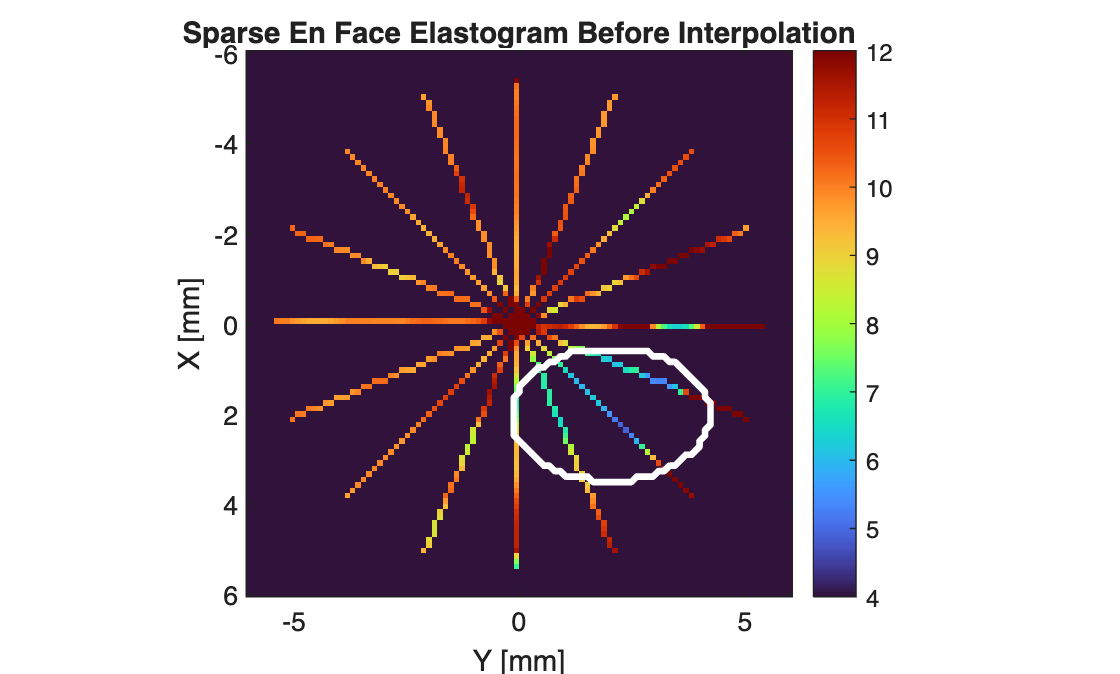

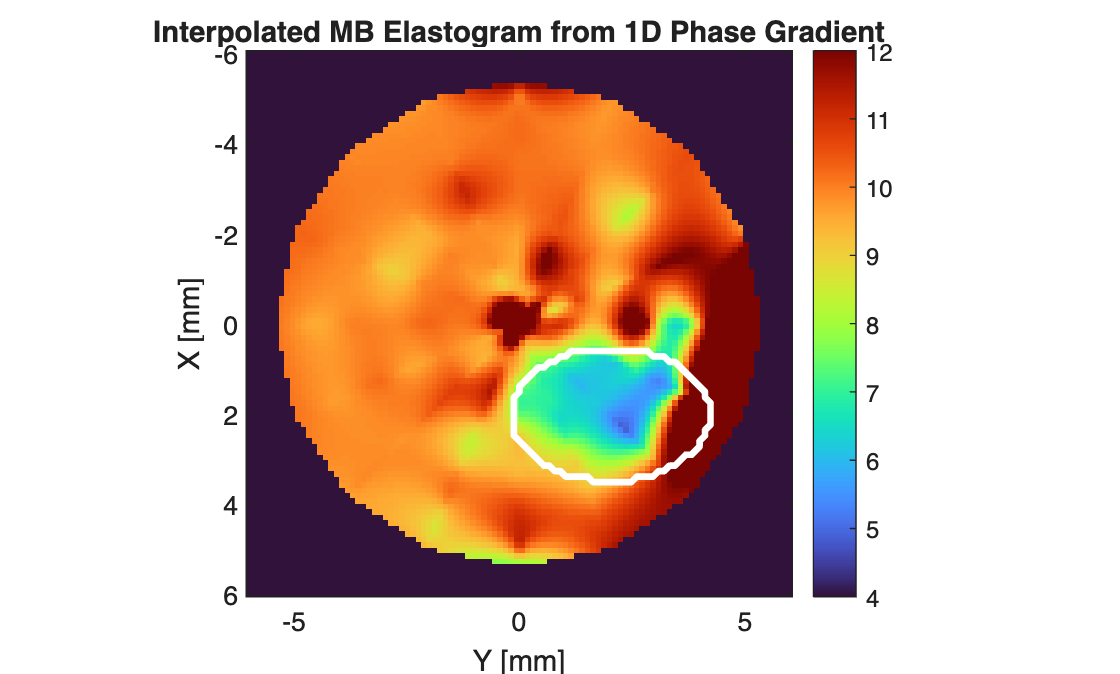

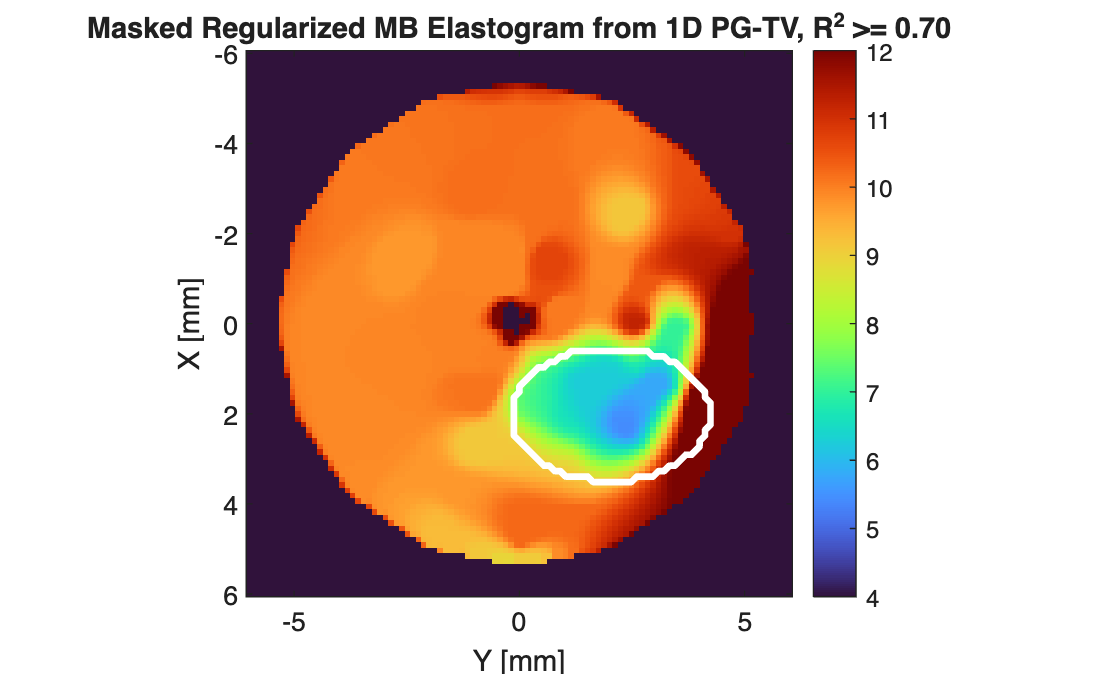

% kernel_size = 11;
% applyTemporalWindow = true;
% clim_limits_PGTV = [4 12];

[Elastogram_MB_1DPG_TV, R2_map_MB_1DPG_TV, Elastogram_Masked_MB_1DPG_TV, ...
 Xgrid_mm_MB_1DPG_TV, Ygrid_mm_MB_1DPG_TV, SparseElastogram_MB_1DPG_TV, ...
 Inc_Mask_MB_1DPG_TV, KVectorField_MB_1DPG_TV] = ...
    PhaseGradient_1D_AlongMeridians_Regularized_TV( ...
        Meridian_Frames_MB, ...
        Inc_Mask, ...
        kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        'R2_thresh', 0.70, ...
        'DisplayResults', true, ...
        'ApplyTemporalHann', applyTemporalWindow, ...
        'InterpMethod', 'natural', ...
        'MuTV', 250, ...
        'TVIterations', 500, ...
        'TVTau', 0.25, ...
        'TVSigma', 0.25, ...
        'TVTheta', 1.0, ...
        'TV_UseR2Mask', false, ...
        'TV_R2Threshold', 0.70, ...
        'MinK', 500, ...
        'MaxK', 8000, ...
        'CLim', [4 12]);

## Metrics Computation using 1D Phase Gradient Along Meridians

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_1DPG, Ea_Inc_1DPG, Ea_Global_1DPG, Ea_Map_1DPG, Ea_Stats_1DPG] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap, Inc_Mask, Bkg_Mask, Elastogram_Masked_MB_1DPG);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 10.2476 m/s | c_GT_mode = 10.0000 m/s | Ea = 2.476 % | N = 4604 pixels
Inclusion:
  c_hat_mean = 8.2140 m/s | c_GT_mode = 6.0000 m/s | Ea = 36.900 % | N = 691 pixels
Global:
  Ea_Global = 19.688 %



Show $E_a$ map:

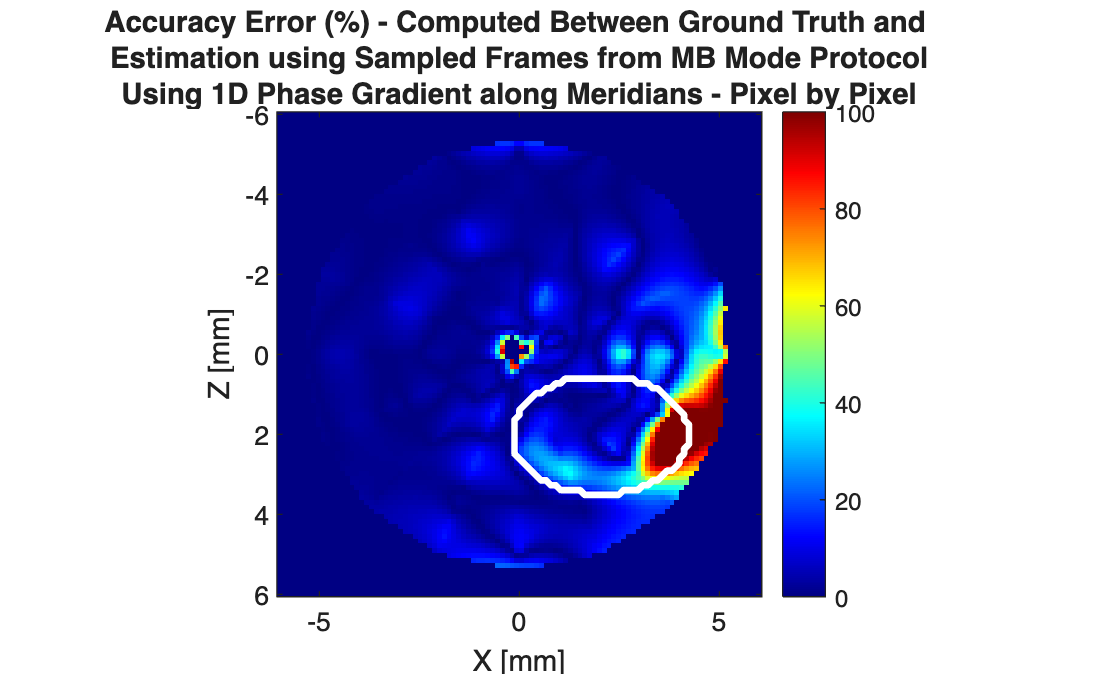

figure, colormap("jet")
imagesc(Xgrid_mm_MB_1DPG, Ygrid_mm_MB_1DPG,Ea_Map_1DPG), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using 1D Phase Gradient along Meridians - Pixel by Pixel"
      });
hold on
Inc_Mask_Ea_1DPG = imresize(logical(Inc_Mask), size(Ea_Map_1DPG), 'nearest');
contour(Xgrid_mm_MB_1DPG, Ygrid_mm_MB_1DPG, double(Inc_Mask_Ea_1DPG), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_1DPG, CNR_ROI_Masks_1DPG, CNR_Stats_1DPG] = Compute_CNR_Masks( ...
    Elastogram_Masked_MB_1DPG, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 10.2476 m/s | std = 1.2808 m/s | N = 4604 pixels
Inclusion : mean = 8.2140 m/s | std = 3.0602 m/s | N = 691 pixels
CNR (Inclusion vs Background) = 0.8669



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_a$** is better**

[Ep_Bkg_1DPG, Ep_Inc_1DPG, Ep_Global_1DPG, Ep_ROI_Masks_1DPG, Ep_Stats_1DPG] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_MB_1DPG, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 12.498 % | mean = 10.2476 m/s | std = 1.2808 m/s | N = 4604 pixels
Inclusion  Ep = 37.255 % | mean = 8.2140 m/s | std = 3.0602 m/s | N = 691 pixels
Global     Ep = 17.684 % | mean = 9.9822 m/s | std = 1.7653 m/s | N = 5295 pixels



## Metrics Computation using Regularized 1D PG-TV Approach (Applying TV after Interpolation)

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_1DPG_TV, Ea_Inc_1DPG_TV, Ea_Global_1DPG_TV, Ea_Map_1DPG_TV, Ea_Stats_1DPG_TV] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap, Inc_Mask, Bkg_Mask, Elastogram_Masked_MB_1DPG_TV);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 10.2186 m/s | c_GT_mode = 10.0000 m/s | Ea = 2.186 % | N = 4604 pixels
Inclusion:
  c_hat_mean = 7.8234 m/s | c_GT_mode = 6.0000 m/s | Ea = 30.390 % | N = 691 pixels
Global:
  Ea_Global = 16.288 %



Show $E_a$ map:

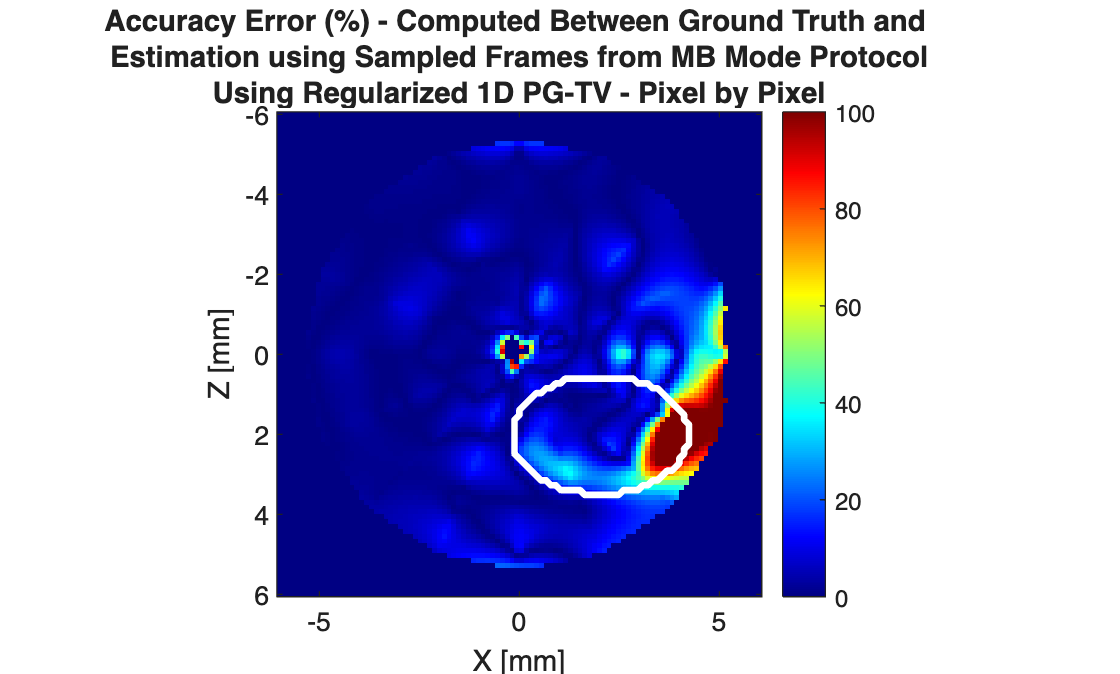

figure, colormap("jet")
imagesc(Xgrid_mm_MB_1DPG, Ygrid_mm_MB_1DPG,Ea_Map_1DPG), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using Regularized 1D PG-TV - Pixel by Pixel"
    });
hold on
Inc_Mask_Ea_1DPG = imresize(logical(Inc_Mask), size(Ea_Map_1DPG), 'nearest');
contour(Xgrid_mm_MB_1DPG, Ygrid_mm_MB_1DPG, double(Inc_Mask_Ea_1DPG), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_1DPG_TV, CNR_ROI_Masks_1DPG_TV, CNR_Stats_1DPG_TV] = Compute_CNR_Masks( ...
    Elastogram_Masked_MB_1DPG_TV, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 10.2186 m/s | std = 1.0905 m/s | N = 4604 pixels
Inclusion : mean = 7.8234 m/s | std = 2.4521 m/s | N = 691 pixels
CNR (Inclusion vs Background) = 1.2622



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_a$** is better**

[Ep_Bkg_1DPG_TV, Ep_Inc_1DPG_TV, Ep_Global_1DPG_TV, Ep_ROI_Masks_1DPG_TV, Ep_Stats_1DPG_TV] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_MB_1DPG_TV, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 10.672 % | mean = 10.2186 m/s | std = 1.0905 m/s | N = 4604 pixels
Inclusion  Ep = 31.344 % | mean = 7.8234 m/s | std = 2.4521 m/s | N = 691 pixels
Global     Ep = 15.861 % | mean = 9.9061 m/s | std = 1.5712 m/s | N = 5295 pixels



## Store Metrics and Elastograms for Analysis

Now we'll store all of the metrics and results 

First, we'll define the type of experiments we've performed, as in the temporal profile of the excitation and wether or not they included saccades:

exp_type = "Harmonic_Saccades";
% Options:
% - "Harmonic_Ideal"
% - "Harmonic_Saccades"
% - "Quasi_Harmonic_Ideal"
% - "Quasi_Harmonic_Saccades"

Then we'll go into the appropriate directory inside our results folder:

exp_path = strcat(run_path,'/',exp_type);
try
    cd(exp_path);
catch
    % If it's not created, then we do so:
    mkdir(exp_path);
end

And now we'll store all of the relevant metrics and Elastograms for the analysis and comparison between multiple MB Multimeridian configurations:

%% ================= Store Metrics and Elastograms =========================

results_filename = sprintf( ...
    "MB_SimResults_%d_Meridians_%s.mat", ...
    Number_Meridians, exp_type);

results_fullpath = fullfile(exp_path, results_filename);

Results = struct();

%% -------------------------- Metadata ----------------------------------- %
Results.Metadata = struct();
Results.Metadata.exp_type = exp_type;
Results.Metadata.protocol_type = protocol_type;
Results.Metadata.Number_Meridians = Number_Meridians;
Results.Metadata.nAscans_per_meridian = nAscans_per_meridian;
Results.Metadata.nAscans = nAscans;
Results.Metadata.nBscans = nBscans;
Results.Metadata.kernel_size = kernel_size;
Results.Metadata.applyTemporalWindow = applyTemporalWindow;
Results.Metadata.clim_limits_2DPG = clim_limits_2DPG;
Results.Metadata.clim_limits_PGTV = clim_limits_PGTV;
Results.Metadata.date_saved = string(datetime("now"));
Results.Metadata.results_filename = results_filename;
Results.Metadata.results_fullpath = results_fullpath;

%% -------------------------- Parameters --------------------------------- %
Results.Parameters = struct();
Results.Parameters.c_medium = c_medium;
Results.Parameters.Ts_OCT = Ts_OCT;
Results.Parameters.T_excitation = T_excitation;
Results.Parameters.alpha = alpha;
Results.Parameters.N_pulses = N_pulses;
Results.Parameters.N_excitations = N_excitations;
Results.Parameters.A_Peak = A_Peak;
Results.Parameters.horizontalMin = horizontalMin;
Results.Parameters.horizontalMax = horizontalMax;
Results.Parameters.verticalMin = verticalMin;
Results.Parameters.verticalMax = verticalMax;
Results.Parameters.nPoints = nPoints;
Results.Parameters.M_repetitions = M_repetitions;
Results.Parameters.nSyncSamples = nSyncSamples;
Results.Parameters.prop_type = prop_type;
Results.Parameters.MotionCase = MotionCase;
Results.Parameters.AcqFramework = AcqFramework;

%% -------------------------- Acquisition / sampling ---------------------- %
Results.Acquisition = struct();
Results.Acquisition.GalvoX = GalvoX;
Results.Acquisition.GalvoY = GalvoY;
Results.Acquisition.Acq_Trigger = Acq_Trigger;
Results.Acquisition.Exc_Trigger = Exc_Trigger;
Results.Acquisition.SamplingInfo_MB = SamplingInfo_MB;

Results.SampledData = struct();
Results.SampledData.Spatial_Frames_Generalized_MB = Spatial_Frames_Generalized_MB;
Results.SampledData.Meridian_Frames_MB = Meridian_Frames_MB;
Results.SampledData.WavePropSim_3DMat_MB_Interp = WavePropSim_3DMat_MB_Interp;
Results.SampledData.ValidMask_MB = ValidMask_MB;
Results.SampledData.HullMask_MB = HullMask_MB;
Results.SampledData.InterpOperator_MB = InterpOperator_MB;

%% -------------------------- Ground truth / masks ------------------------ %
Results.GroundTruth = struct();
Results.GroundTruth.GT_SpeedMap = GT_SpeedMap;
Results.GroundTruth.Inc_Mask = Inc_Mask;
Results.GroundTruth.Bkg_Mask = Bkg_Mask;
Results.GroundTruth.Inc_Mask_ReducedMBGrid = Inc_Mask_ReducedMBGrid;
Results.GroundTruth.Bkg_Mask_ReducedMBGrid = Bkg_Mask_ReducedMBGrid;

%% ========================== Store estimator outputs ===================== %

%% -------------------------- 1D-PG -------------------------------------- %
Results.MB_1DPG = struct();

Results.MB_1DPG.Elastogram = Elastogram_MB_1DPG;
Results.MB_1DPG.Elastogram_Masked = Elastogram_Masked_MB_1DPG;
Results.MB_1DPG.R2_map = R2_map_MB_1DPG;
Results.MB_1DPG.Xaxis_mm = Xgrid_mm_MB_1DPG;
Results.MB_1DPG.Yaxis_mm = Ygrid_mm_MB_1DPG;
Results.MB_1DPG.SparseElastogram = SparseElastogram_MB_1DPG;
Results.MB_1DPG.Inc_Mask_Grid = Inc_Mask_MB_1DPG;
Results.MB_1DPG.KVectorField = KVectorField_MB_1DPG;

Results.MB_1DPG.AccuracyError = struct();
Results.MB_1DPG.AccuracyError.Ea_Bkg = Ea_Bkg_1DPG;
Results.MB_1DPG.AccuracyError.Ea_Inc = Ea_Inc_1DPG;
Results.MB_1DPG.AccuracyError.Ea_Global = Ea_Global_1DPG;
Results.MB_1DPG.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_1DPG;
Results.MB_1DPG.AccuracyError.Ea_Stats = Ea_Stats_1DPG;

Results.MB_1DPG.CNR = struct();
Results.MB_1DPG.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_1DPG;
Results.MB_1DPG.CNR.CNR_ROI_Masks = CNR_ROI_Masks_1DPG;
Results.MB_1DPG.CNR.CNR_Stats = CNR_Stats_1DPG;

Results.MB_1DPG.PrecisionError = struct();
Results.MB_1DPG.PrecisionError.Ep_Bkg = Ep_Bkg_1DPG;
Results.MB_1DPG.PrecisionError.Ep_Inc = Ep_Inc_1DPG;
Results.MB_1DPG.PrecisionError.Ep_Global = Ep_Global_1DPG;
Results.MB_1DPG.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_1DPG;
Results.MB_1DPG.PrecisionError.Ep_Stats = Ep_Stats_1DPG;

%% -------------------------- 1D-PG-TV ----------------------------------- %
Results.MB_1DPG_TV = struct();

Results.MB_1DPG_TV.Elastogram = Elastogram_MB_1DPG_TV;
Results.MB_1DPG_TV.Elastogram_Masked = Elastogram_Masked_MB_1DPG_TV;
Results.MB_1DPG_TV.R2_map = R2_map_MB_1DPG_TV;
Results.MB_1DPG_TV.Xaxis_mm = Xgrid_mm_MB_1DPG_TV;
Results.MB_1DPG_TV.Yaxis_mm = Ygrid_mm_MB_1DPG_TV;
Results.MB_1DPG_TV.SparseElastogram = SparseElastogram_MB_1DPG_TV;
Results.MB_1DPG_TV.Inc_Mask_Grid = Inc_Mask_MB_1DPG_TV;
Results.MB_1DPG_TV.KVectorField = KVectorField_MB_1DPG_TV;

Results.MB_1DPG_TV.AccuracyError = struct();
Results.MB_1DPG_TV.AccuracyError.Ea_Bkg = Ea_Bkg_1DPG_TV;
Results.MB_1DPG_TV.AccuracyError.Ea_Inc = Ea_Inc_1DPG_TV;
Results.MB_1DPG_TV.AccuracyError.Ea_Global = Ea_Global_1DPG_TV;
Results.MB_1DPG_TV.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_1DPG_TV;
Results.MB_1DPG_TV.AccuracyError.Ea_Stats = Ea_Stats_1DPG_TV;

Results.MB_1DPG_TV.CNR = struct();
Results.MB_1DPG_TV.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_1DPG_TV;
Results.MB_1DPG_TV.CNR.CNR_ROI_Masks = CNR_ROI_Masks_1DPG_TV;
Results.MB_1DPG_TV.CNR.CNR_Stats = CNR_Stats_1DPG_TV;

Results.MB_1DPG_TV.PrecisionError = struct();
Results.MB_1DPG_TV.PrecisionError.Ep_Bkg = Ep_Bkg_1DPG_TV;
Results.MB_1DPG_TV.PrecisionError.Ep_Inc = Ep_Inc_1DPG_TV;
Results.MB_1DPG_TV.PrecisionError.Ep_Global = Ep_Global_1DPG_TV;
Results.MB_1DPG_TV.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_1DPG_TV;
Results.MB_1DPG_TV.PrecisionError.Ep_Stats = Ep_Stats_1DPG_TV;

%% -------------------------- 2D-PG -------------------------------------- %
Results.MB_2DPG = struct();

Results.MB_2DPG.Elastogram = Elastogram_MB_2DPG;
Results.MB_2DPG.Elastogram_Masked = Elastogram_Masked_MB_2DPG;
Results.MB_2DPG.R2_map = R2_map_MB_2DPG;
Results.MB_2DPG.Xaxis_mm = Xcrop_mm_MB_2DPG;
Results.MB_2DPG.Yaxis_mm = Ycrop_mm_MB_2DPG;
Results.MB_2DPG.Complex_Field_Vz = Complex_Field_Vz_MB_2DPG;
Results.MB_2DPG.Inc_Mask_Crop = Inc_Mask_Crop_MB_2DPG;
Results.MB_2DPG.Bkg_Mask_Crop = Bkg_Mask_Crop_MB_2DPG;
Results.MB_2DPG.Kx = Kx_MB_2DPG;
Results.MB_2DPG.Ky = Ky_MB_2DPG;
Results.MB_2DPG.Kmag = Kmag_MB_2DPG;

Results.MB_2DPG.AccuracyError = struct();
Results.MB_2DPG.AccuracyError.Ea_Bkg = Ea_Bkg_2DPG;
Results.MB_2DPG.AccuracyError.Ea_Inc = Ea_Inc_2DPG;
Results.MB_2DPG.AccuracyError.Ea_Global = Ea_Global_2DPG;
Results.MB_2DPG.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_2DPG;
Results.MB_2DPG.AccuracyError.Ea_Stats = Ea_Stats_2DPG;

Results.MB_2DPG.CNR = struct();
Results.MB_2DPG.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_2DPG;
Results.MB_2DPG.CNR.CNR_ROI_Masks = CNR_ROI_Masks_2DPG;
Results.MB_2DPG.CNR.CNR_Stats = CNR_Stats_2DPG;

Results.MB_2DPG.PrecisionError = struct();
Results.MB_2DPG.PrecisionError.Ep_Bkg = Ep_Bkg_2DPG;
Results.MB_2DPG.PrecisionError.Ep_Inc = Ep_Inc_2DPG;
Results.MB_2DPG.PrecisionError.Ep_Global = Ep_Global_2DPG;
Results.MB_2DPG.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_2DPG;
Results.MB_2DPG.PrecisionError.Ep_Stats = Ep_Stats_2DPG;

%% -------------------------- 2D-PG-TV ----------------------------------- %
Results.MB_2DPG_TV = struct();

Results.MB_2DPG_TV.Elastogram = Elastogram_MB_2DPG_TV;
Results.MB_2DPG_TV.Elastogram_Masked = Elastogram_Masked_MB_2DPG_TV;
Results.MB_2DPG_TV.Elastogram_raw = Elastogram_raw_MB_2DPG_TV;
Results.MB_2DPG_TV.R2_map = R2_map_MB_2DPG_TV;
Results.MB_2DPG_TV.Xaxis_mm = Xcrop_mm_MB_2DPG_TV;
Results.MB_2DPG_TV.Yaxis_mm = Ycrop_mm_MB_2DPG_TV;
Results.MB_2DPG_TV.Complex_Field_Vz = Complex_Field_Vz_MB_2DPG_TV;
Results.MB_2DPG_TV.Inc_Mask_Crop = Inc_Mask_Crop_MB_2DPG_TV;
Results.MB_2DPG_TV.Bkg_Mask_Crop = Bkg_Mask_Crop_MB_2DPG_TV;
Results.MB_2DPG_TV.Kx = Kx_MB_2DPG_TV;
Results.MB_2DPG_TV.Ky = Ky_MB_2DPG_TV;
Results.MB_2DPG_TV.Kmag_raw = Kmag_MB_2DPG_TV;
Results.MB_2DPG_TV.Kmag_TV = Kmag_TV_MB_2DPG_TV;
Results.MB_2DPG_TV.TVInfo = TVInfo_MB_2DPG_TV;

Results.MB_2DPG_TV.AccuracyError = struct();
Results.MB_2DPG_TV.AccuracyError.Ea_Bkg = Ea_Bkg_2DPG_TV;
Results.MB_2DPG_TV.AccuracyError.Ea_Inc = Ea_Inc_2DPG_TV;
Results.MB_2DPG_TV.AccuracyError.Ea_Global = Ea_Global_2DPG_TV;
Results.MB_2DPG_TV.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_2DPG_TV;
Results.MB_2DPG_TV.AccuracyError.Ea_Stats = Ea_Stats_2DPG_TV;

Results.MB_2DPG_TV.CNR = struct();
Results.MB_2DPG_TV.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_2DPG_TV;
Results.MB_2DPG_TV.CNR.CNR_ROI_Masks = CNR_ROI_Masks_2DPG_TV;
Results.MB_2DPG_TV.CNR.CNR_Stats = CNR_Stats_2DPG_TV;

Results.MB_2DPG_TV.PrecisionError = struct();
Results.MB_2DPG_TV.PrecisionError.Ep_Bkg = Ep_Bkg_2DPG_TV;
Results.MB_2DPG_TV.PrecisionError.Ep_Inc = Ep_Inc_2DPG_TV;
Results.MB_2DPG_TV.PrecisionError.Ep_Global = Ep_Global_2DPG_TV;
Results.MB_2DPG_TV.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_2DPG_TV;
Results.MB_2DPG_TV.PrecisionError.Ep_Stats = Ep_Stats_2DPG_TV;

%% ========================== Summary table ===============================

MetricNames = [
    "Mean Wave Phase Speed [m/s] ± std - Inclusion"
    "Mean Wave Phase Speed [m/s] ± std - Background"
    "Global Accuracy Error Ea [%] - Inclusion"
    "Global Accuracy Error Ea [%] - Background"
    "Global Accuracy Error Ea [%] - Global"
    "Precision Error Ep [%] - Inclusion"
    "Precision Error Ep [%] - Background"
    "Precision Error Ep [%] - Global"
    "Contrast to Noise Ratio CNR - Inclusion vs Background"
];

Summary_1DPG = [
    format_mean_std_from_mask(Elastogram_Masked_MB_1DPG, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_MB_1DPG, Bkg_Mask)
    format_scalar(Ea_Inc_1DPG)
    format_scalar(Ea_Bkg_1DPG)
    format_scalar(Ea_Global_1DPG)
    format_scalar(Ep_Inc_1DPG)
    format_scalar(Ep_Bkg_1DPG)
    format_scalar(Ep_Global_1DPG)
    format_scalar(CNR_Inc_vs_Bkg_1DPG)
];

Summary_1DPG_TV = [
    format_mean_std_from_mask(Elastogram_Masked_MB_1DPG_TV, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_MB_1DPG_TV, Bkg_Mask)
    format_scalar(Ea_Inc_1DPG_TV)
    format_scalar(Ea_Bkg_1DPG_TV)
    format_scalar(Ea_Global_1DPG_TV)
    format_scalar(Ep_Inc_1DPG_TV)
    format_scalar(Ep_Bkg_1DPG_TV)
    format_scalar(Ep_Global_1DPG_TV)
    format_scalar(CNR_Inc_vs_Bkg_1DPG_TV)
];

Summary_2DPG = [
    format_mean_std_from_mask(Elastogram_Masked_MB_2DPG, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_MB_2DPG, Bkg_Mask)
    format_scalar(Ea_Inc_2DPG)
    format_scalar(Ea_Bkg_2DPG)
    format_scalar(Ea_Global_2DPG)
    format_scalar(Ep_Inc_2DPG)
    format_scalar(Ep_Bkg_2DPG)
    format_scalar(Ep_Global_2DPG)
    format_scalar(CNR_Inc_vs_Bkg_2DPG)
];

Summary_2DPG_TV = [
    format_mean_std_from_mask(Elastogram_Masked_MB_2DPG_TV, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_MB_2DPG_TV, Bkg_Mask)
    format_scalar(Ea_Inc_2DPG_TV)
    format_scalar(Ea_Bkg_2DPG_TV)
    format_scalar(Ea_Global_2DPG_TV)
    format_scalar(Ep_Inc_2DPG_TV)
    format_scalar(Ep_Bkg_2DPG_TV)
    format_scalar(Ep_Global_2DPG_TV)
    format_scalar(CNR_Inc_vs_Bkg_2DPG_TV)
];

Results.SummaryTable = table( ...
    MetricNames, ...
    Summary_1DPG, ...
    Summary_1DPG_TV, ...
    Summary_2DPG, ...
    Summary_2DPG_TV);

Results.SummaryTable.Properties.VariableNames = { ...
    'Metric', '1D_PG', '1D_PG_TV', '2D_PG', '2D_PG_TV'};

%% -------------------------- Save .mat file ------------------------------ %

save(results_fullpath, "Results", "-v7.3");

fprintf("\n===== MB PG / PG-TV Simulation Results Saved =====\n");


===== MB PG / PG-TV Simulation Results Saved =====


fprintf("Experiment type : %s\n", exp_type);

Experiment type : Harmonic_Saccades


fprintf("Protocol        : %s\n", protocol_type);

Protocol        : Multimeridian_MB


fprintf("Meridians       : %d\n", Number_Meridians);

Meridians       : 8


fprintf("Saved file      : %s\n", results_fullpath);

Saved file      : /Users/cesarestefanomachadoferrer/Desktop/Undergrad Thesis/Definitive Acquisition Sampling Simulations/Results/Multimeridian_MB/8 Meridians/Harmonic_Saccades/MB_SimResults_8_Meridians_Harmonic_Saccades.mat



disp(Results.SummaryTable);

                            Metric                                   1D_PG                1D_PG_TV               2D_PG              2D_PG_TV     
    _______________________________________________________    __________________    __________________    _________________    _________________

    "Mean Wave Phase Speed [m/s] ± std - Inclusion"            "8.2140 ± 3.0602"     "7.8234 ± 2.4521"     "6.4593 ± 1.0167"    "6.5076 ± 0.9638"
    "Mean Wave Phase Speed [m/s] ± std - Background"           "10.2476 ± 1.2808"    "10.2186 ± 1.0905"    "9.9308 ± 0.8888"    "9.9973 ± 0.8286"
    "Global Accuracy Error Ea [%] - Inclusion"                 "36.9004"             "30.3898"             "7.6546"             "8.4595"         
    "Global Accuracy Error Ea [%] - Background"                "2.4762"              "2.1864"      


%% ========================== Local helper functions ======================

function out = format_mean_std_from_mask(Elastogram, Mask)

    if ~isequal(size(Elastogram), size(Mask))
        Mask = imresize(logical(Mask), size(Elastogram), 'nearest');
    else
        Mask = logical(Mask);
    end

    vals = Elastogram(Mask);
    vals = vals(isfinite(vals));

    if isempty(vals)
        out = "NaN ± NaN";
    else
        out = sprintf("%.4f ± %.4f", mean(vals,'omitnan'), std(vals,0,'omitnan'));
        out = string(out);
    end
end

function out = format_scalar(x)

    if isempty(x) || ~isfinite(x)
        out = "NaN";
    else
        out = string(sprintf("%.4f", x));
    end
end

End timer:

toc

Elapsed time is 265.956326 seconds.
